First we read the logos and make their features ready.

x=imread('courses\image project\logo\h1.PNG');
y=imread('courses\image project\logo\h2.PNG');
z=imread('courses\image project\logo\k.PNG');
x1=imread('courses\image project\logo\op.PNG');


d1=im2gray(x);
d2=im2gray(y);
d3=im2gray(z);
d4=im2gray(x1);



fftD1=fft2(double(d1));
d1features=abs(fftD1(:));
d1features=sort(d1features,'descend');
d1features=d1features(1:3);

fftD2=fft2(double(d2));
d2features=abs(fftD2(:));
d2features=sort(d2features,'descend');
d2features=d2features(1:3);


fftD3=fft2(double(d3));
d3features=abs(fftD3(:));
d3features=sort(d3features,'descend');
d3features=d3features(1:3);

fftD4=fft2(double(d4));
d4features=abs(fftD4(:));
d4features=sort(d4features,'descend');
d4features=d4features(1:3);



features=[d1features,d2features,d3features,d4features];

%Failed experment
% x=imread('courses\image project\logo\h1.PNG');
% y=imread('courses\image project\logo\h2.PNG');
% z=imread('courses\image project\logo\k.PNG');
% x1=imread('courses\image project\logo\op.PNG');
% 
% 
% d1=im2gray(x);
% d2=im2gray(y);
% d3=im2gray(z);
% d4=im2gray(x1);
% 
% 
% 
% p1=detectSURFFeatures(d1);
% f1=extractFeatures(d1,p1);
% 
% p2=detectSURFFeatures(d2);
% f2=extractFeatures(d2,p2);
% 
% p3=detectSURFFeatures(d3);
% f3=extractFeatures(d3,p3);
% 
% p4=detectSURFFeatures(d4);
% f4=extractFeatures(d4,p4);
% 
% 
% 
% features=[f1,f2,f3,f4];



Now we read our first photo we make it to grayscale.

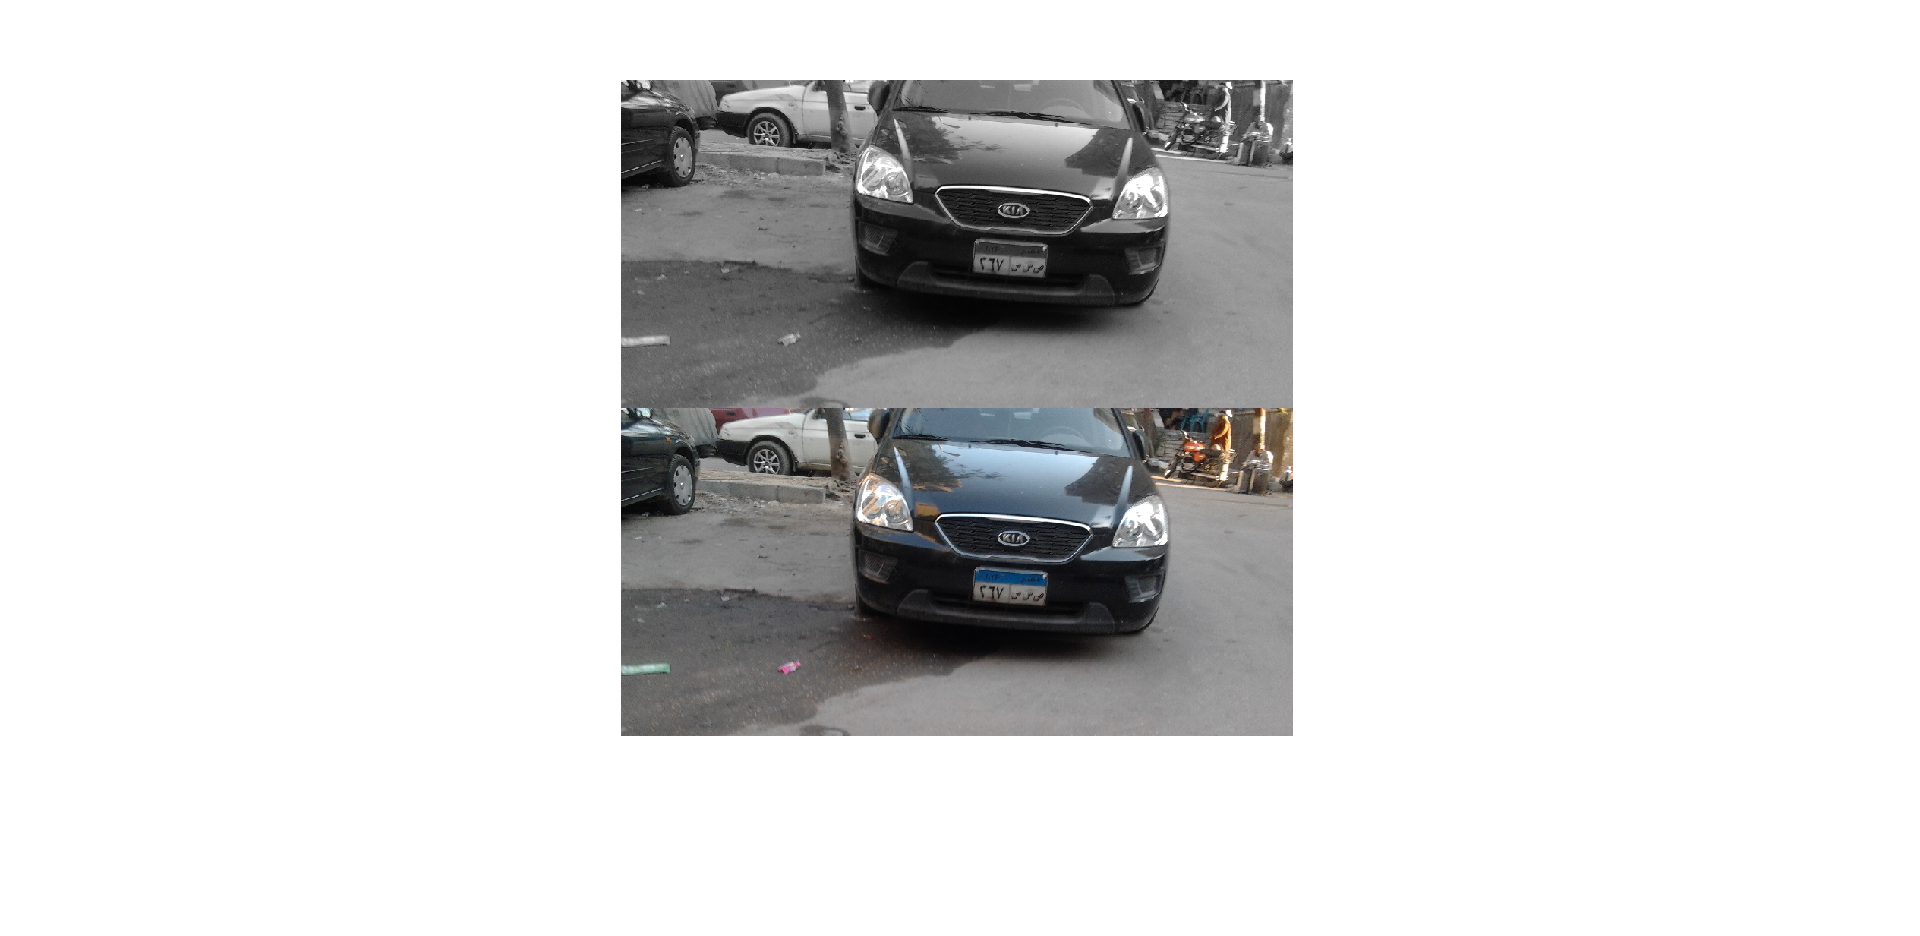

imgg = imread("courses\image project\Case2\Case2-Front2.jpg");

img = im2gray(imgg);

montage({img,imgg});

%imtool(imgg)

Then we do edge detection and apply some filters to try to isolate our logo.

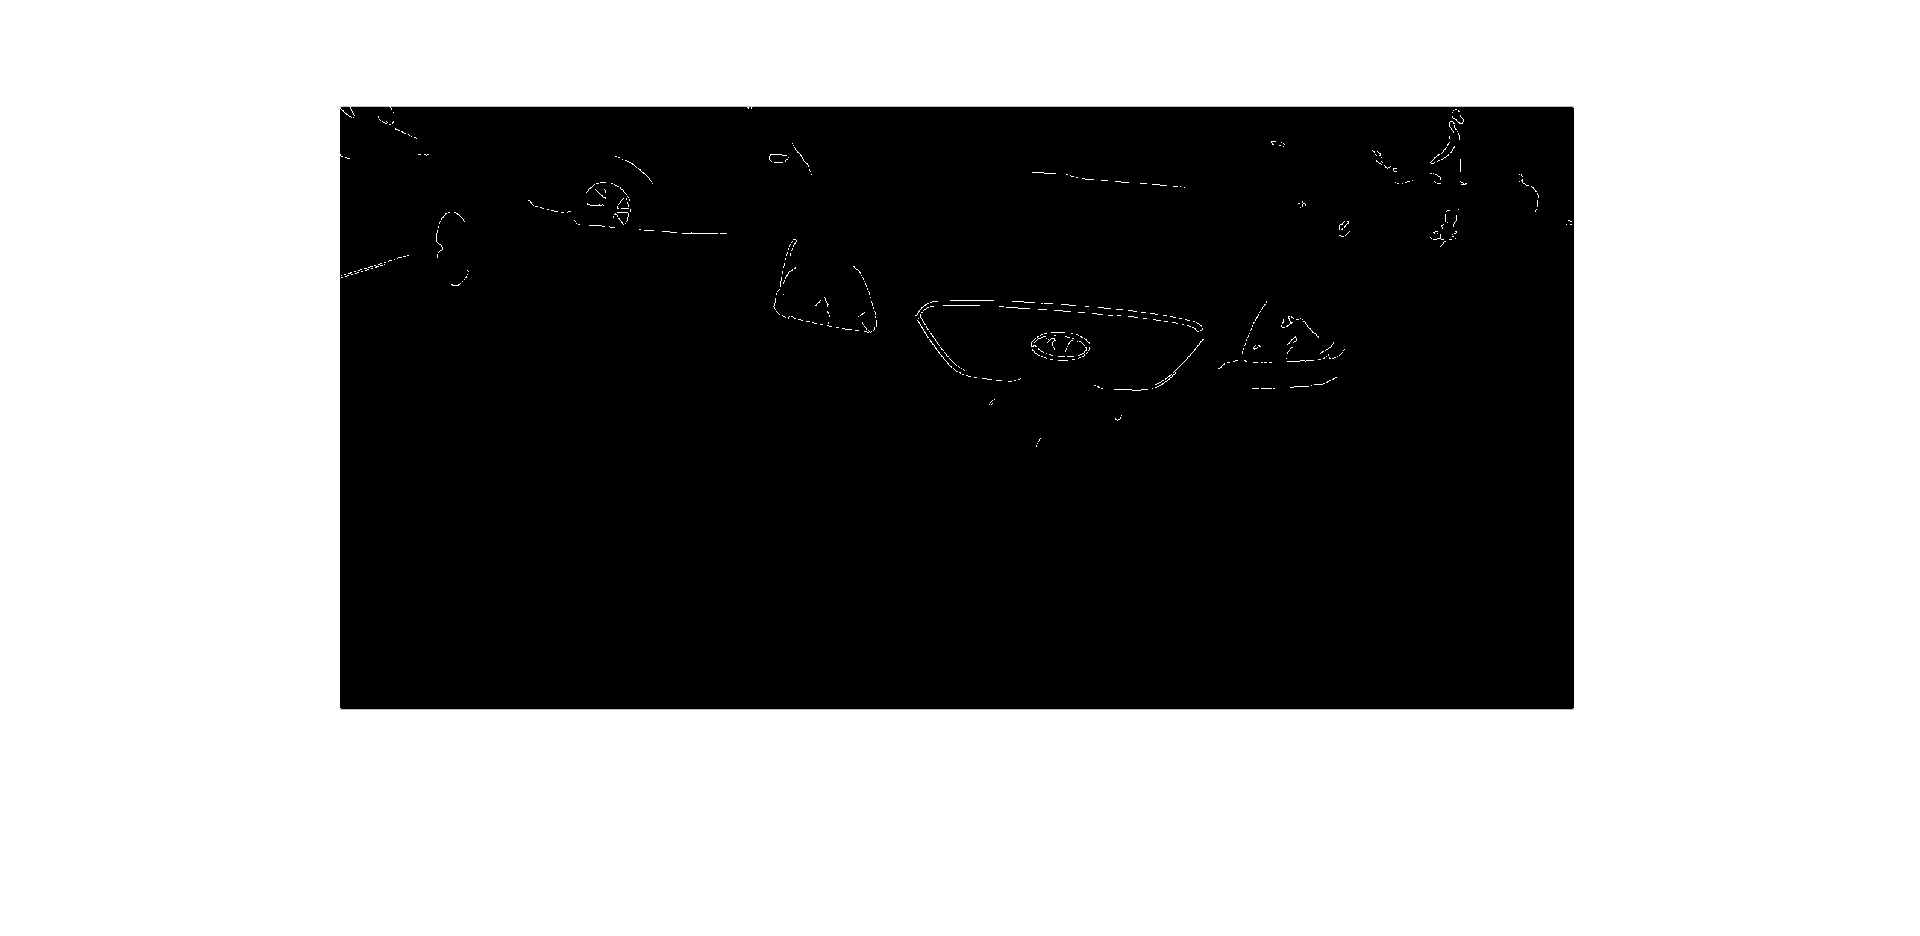

imgFilt = medfilt2(img,[5 5]);
imge = edge(imgFilt,"approxcanny",0.4);
imshow(imge)

se = strel("disk", 5)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [9×9 logical]
    Dimensionality: 2


imge = imclose(imge,se)

imge = 1000×2048 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

imge = imfill(imge,"holes")

imge = 1000×2048 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

imge = imopen(imge,se)

imge = 1000×2048 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

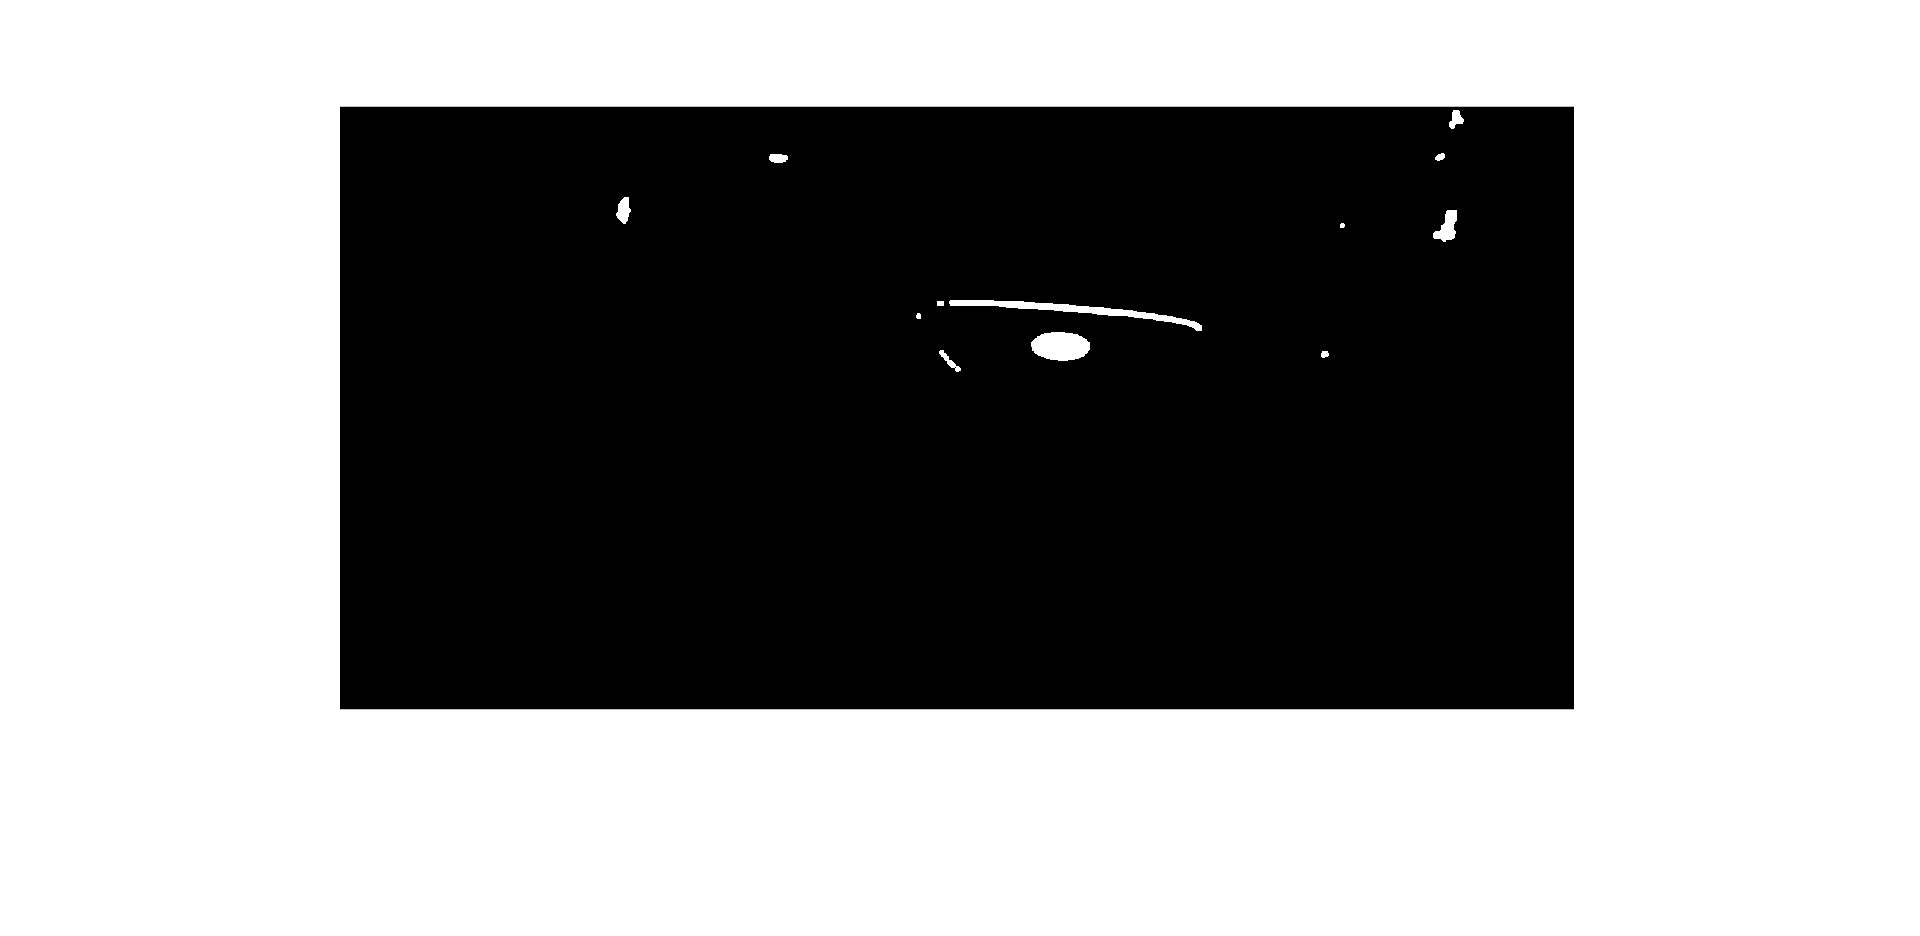

imshow(imge)

then we do this function that i bulid that try segmenting in other way. its explianed in the function file.

gg = segmentImagev2(imgFilt)

gg = 1000×2048 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

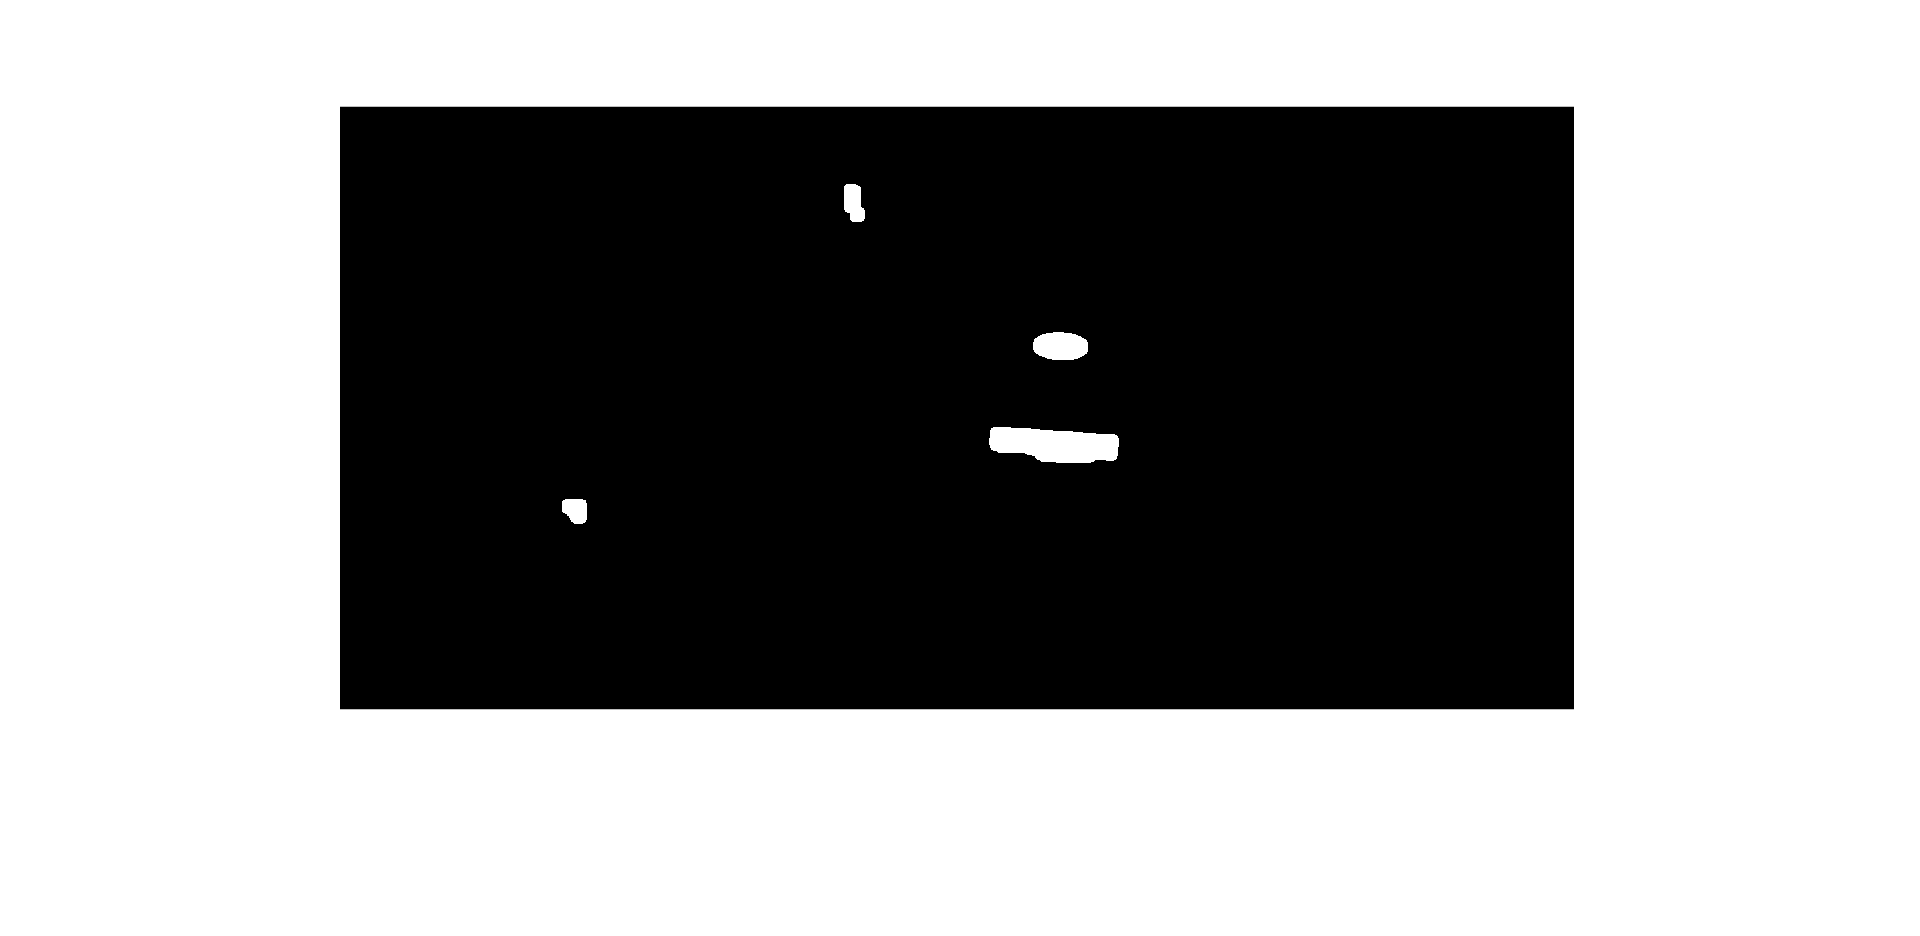

imshow(gg)

then we apply both of them at the same time to leave only the logo.

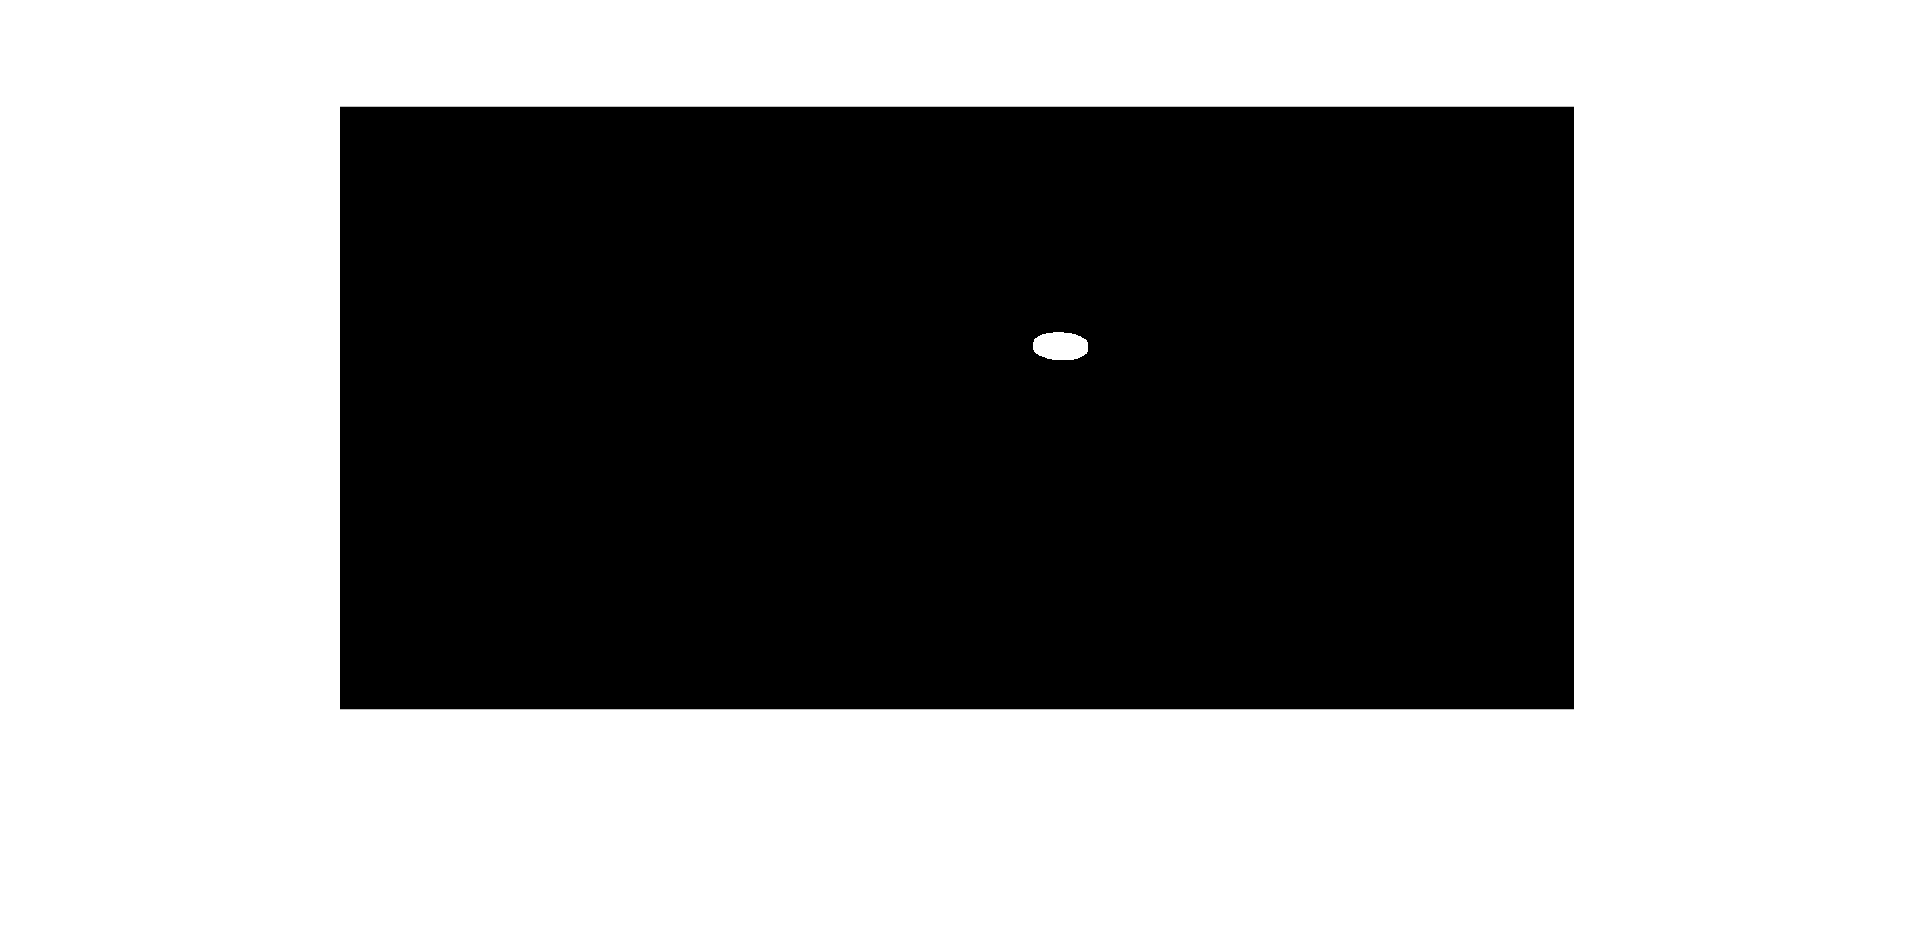

ff = gg & imge;
imshow(ff)

then we use regionprops which is a function that gets me some info about the segmented region in my photo which is the logo so im intreasted in the boundingbox array cause i want to crop my image and only leave the logo.

logoinfo=regionprops(ff)

logoinfo = struct with fields:
           Area: 3539
       Centroid: [1.1965e+03 398.0893]
    BoundingBox: [1.1505e+03 374.5000 92 47]


logo = imcrop(imgg,logoinfo.BoundingBox)

logo = 48×93×3 uint8 array
logo(:,:,1) =

    37    39    35    38    41    40    44    51    52    55    62    56    56    53    51    48    43    44    47    48    37    27    25    24    35    37    41    51    50    49    63    76    84    92    97    97    94    92   106   119   127   124   118   107   104   110   113   104    97    98    93    96    81    63    56    59    62    53    40    40    39    35    43    39    33    28    22    29    35    38    41    43    43    41    32    32    36    35    32    28    27    24    17    19    18    11     4     6    14    18    21    16    17
    33    32    40    37    41    45    46    47    49    57    63    53    49    45    44    41    29    26    29    38    35    40    43    55    78    92   101   114   110   106   119   128   122   121   127   129   133   132   131   134   136   134   132   131   129   127   127   129   123   118   125   130   127   124   116   106   108   107    94    88    71    52    60    65    59    42   

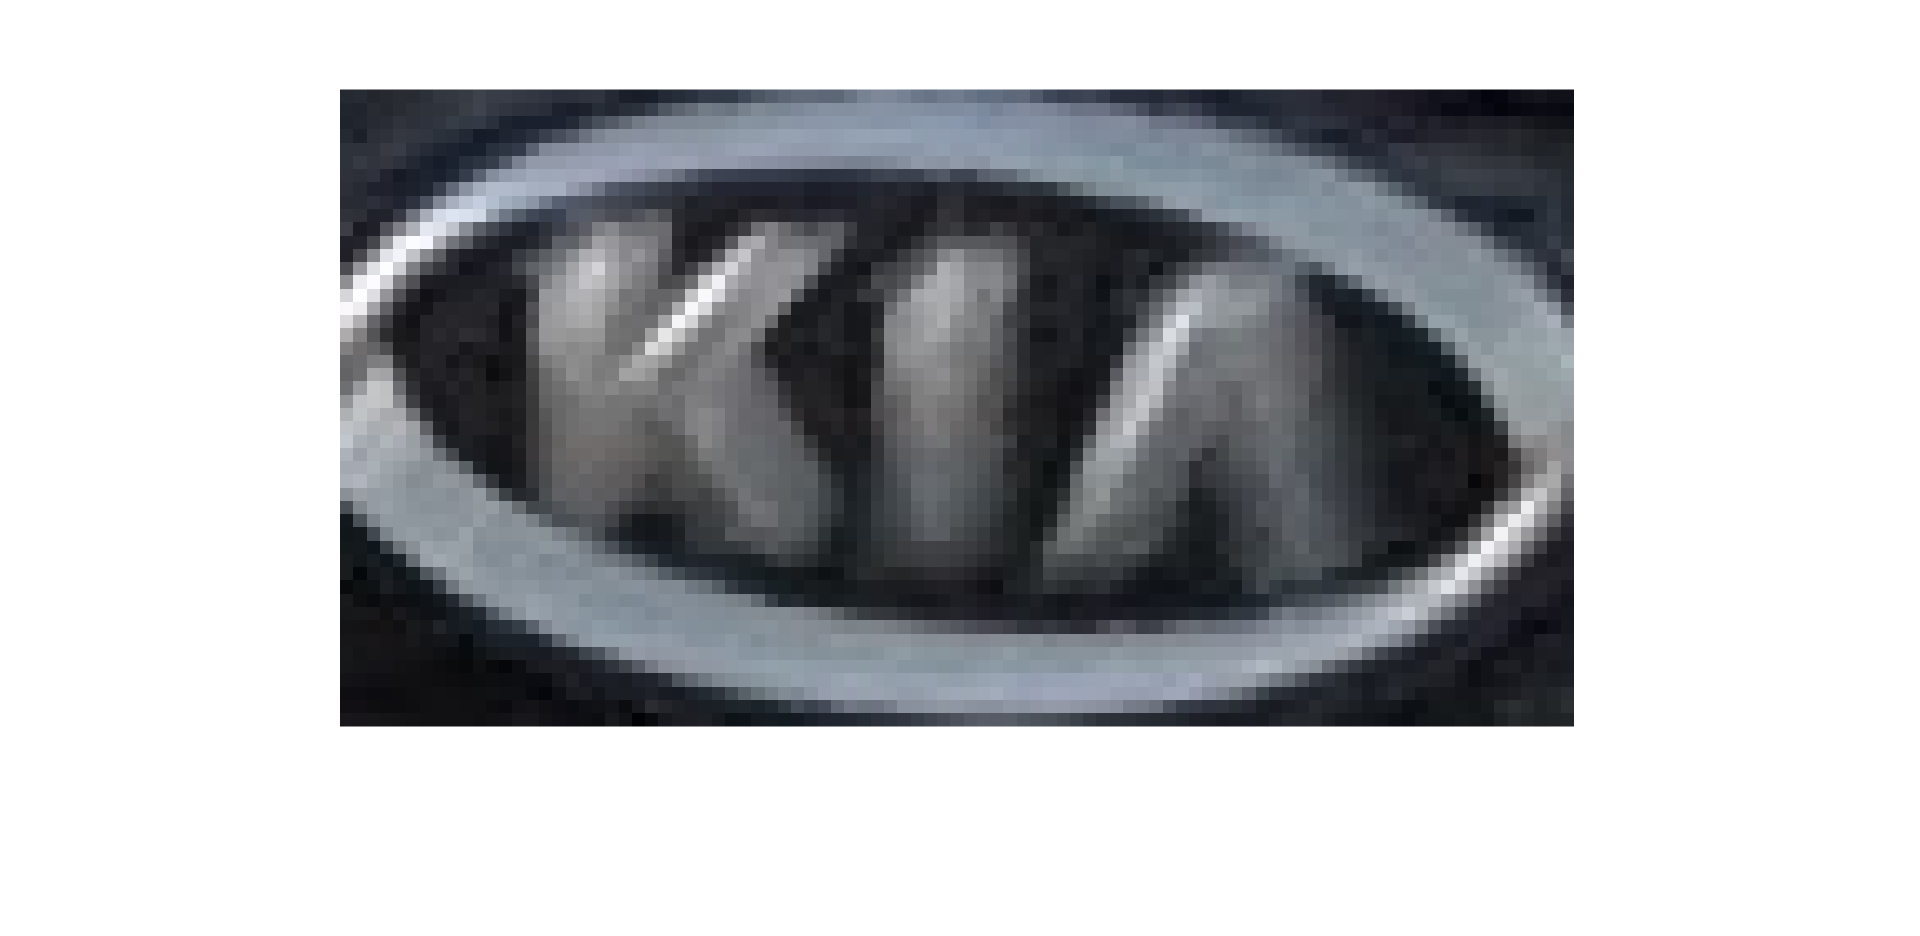


imshow(logo)

logo = im2gray(logo)

logo = 48×93 uint8 matrix
    41    43    38    41    44    43    48    55    56    59    66    60    60    57    55    52    47    48    51    52    41    31    29    30    41    44    48    58    57    57    71    84    92   100   105   105   102   102   114   129   135   134   128   118   114   121   123   115   108   109
    37    36    43    40    44    48    50    51    53    61    67    57    53    49    48    45    33    30    33    44    39    46    49    62    85    99   108   122   118   114   127   136   132   131   135   139   143   142   141   144   146   145   143   142   140   138   138   140   136   129
    35    38    42    44    51    48    50    53    60    56    57    48    35    31    32    32    34    42    62    78    90   105   122   130   134   134   134   136   136   140   145   144   143   148   147   149   149   150   150   148   145   146   147   151   152   150   150   146   139   142
    41    32    47    49    56    54    53    48    46    40    27    2

logo = filter2(fspecial('average',3),logo)/255;

then we ably feature detection on the logo image.

image=logo;

fftI=fft2(double(image));
imagefeatures=abs(fftI(:));
imagefeatures=sort(imagefeatures,'descend');
imagefeatures=imagefeatures(1:3);

for i=1:4
nearesy(i)=sqrt((imagefeatures(1)-features(1,i))^2+(imagefeatures(2)-features(2,i))^2+(imagefeatures(3)-features(3,i))^2);
end

nearesy

nearesy = 	1.0e+06 *

    1.8938    0.7096    1.5492    5.3193


[MinResult,Index]=min(nearesy)

MinResult = 7.0960e+05

Index = 2

now our second image.

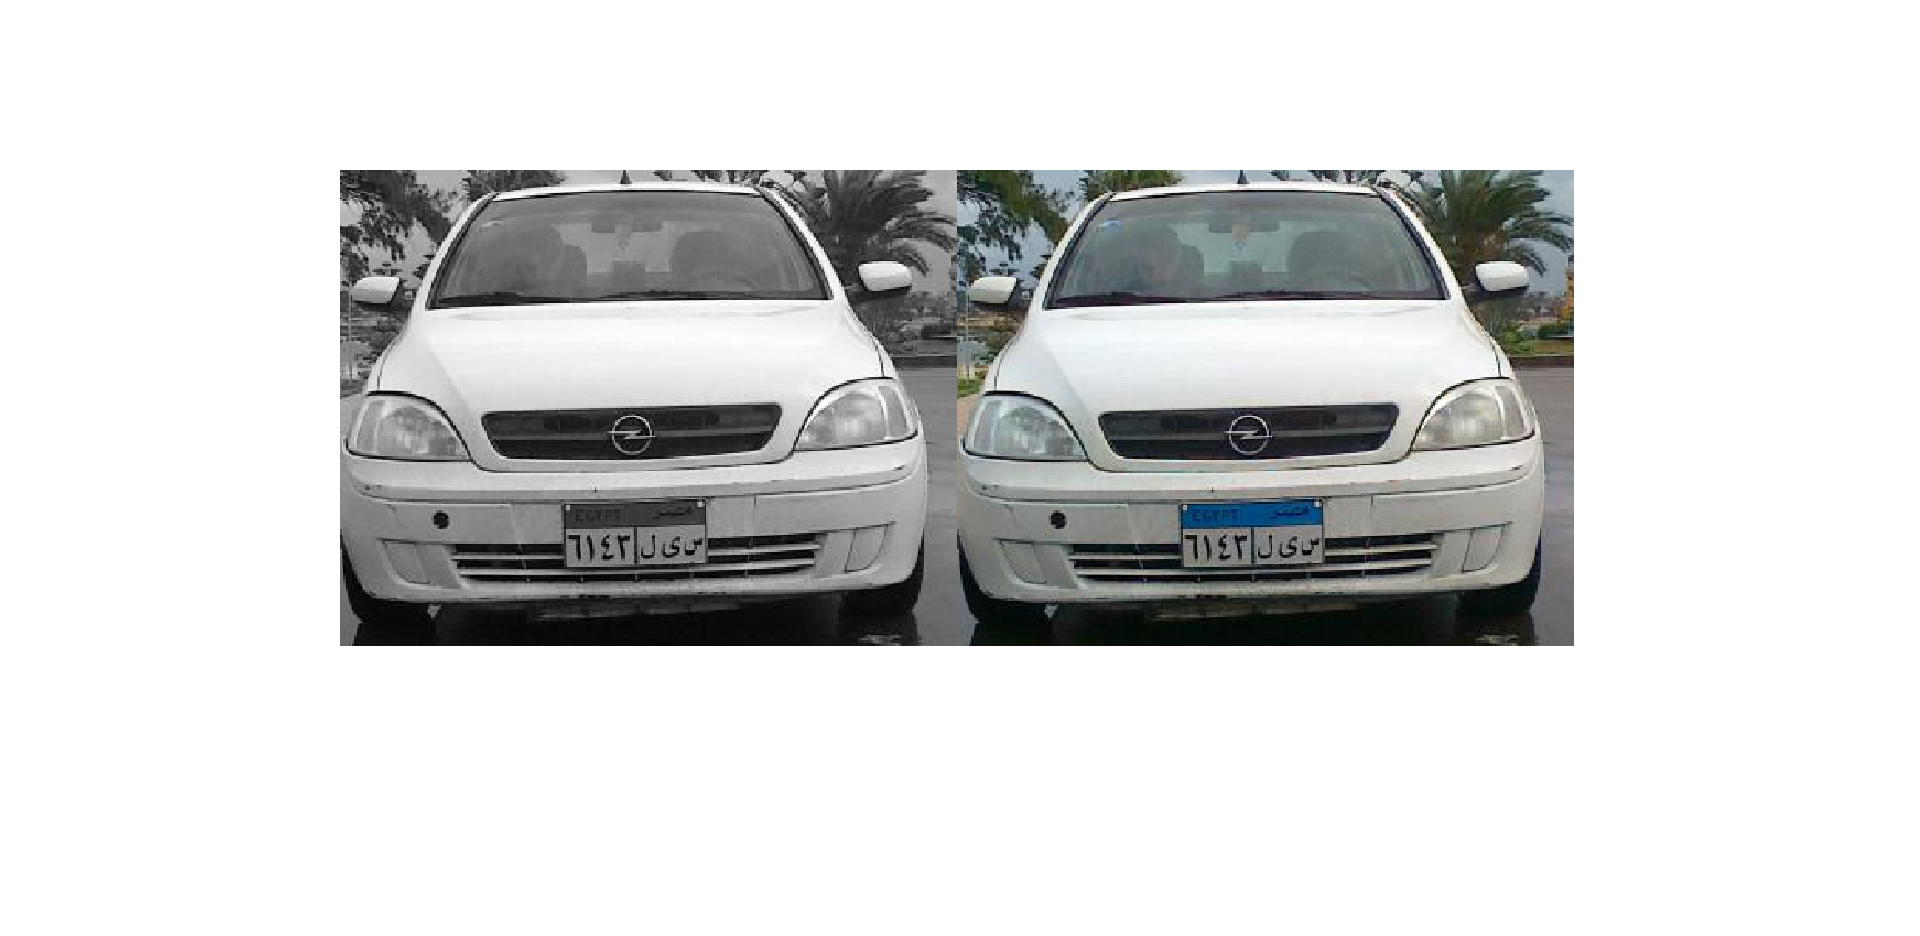

imgg2 = imread("courses\image project\Case1\Case1-Front1.bmp");

img2 = im2gray(imgg2);

montage({img2,imgg2});

i took a diffrent aprouch on this one first we got edges.

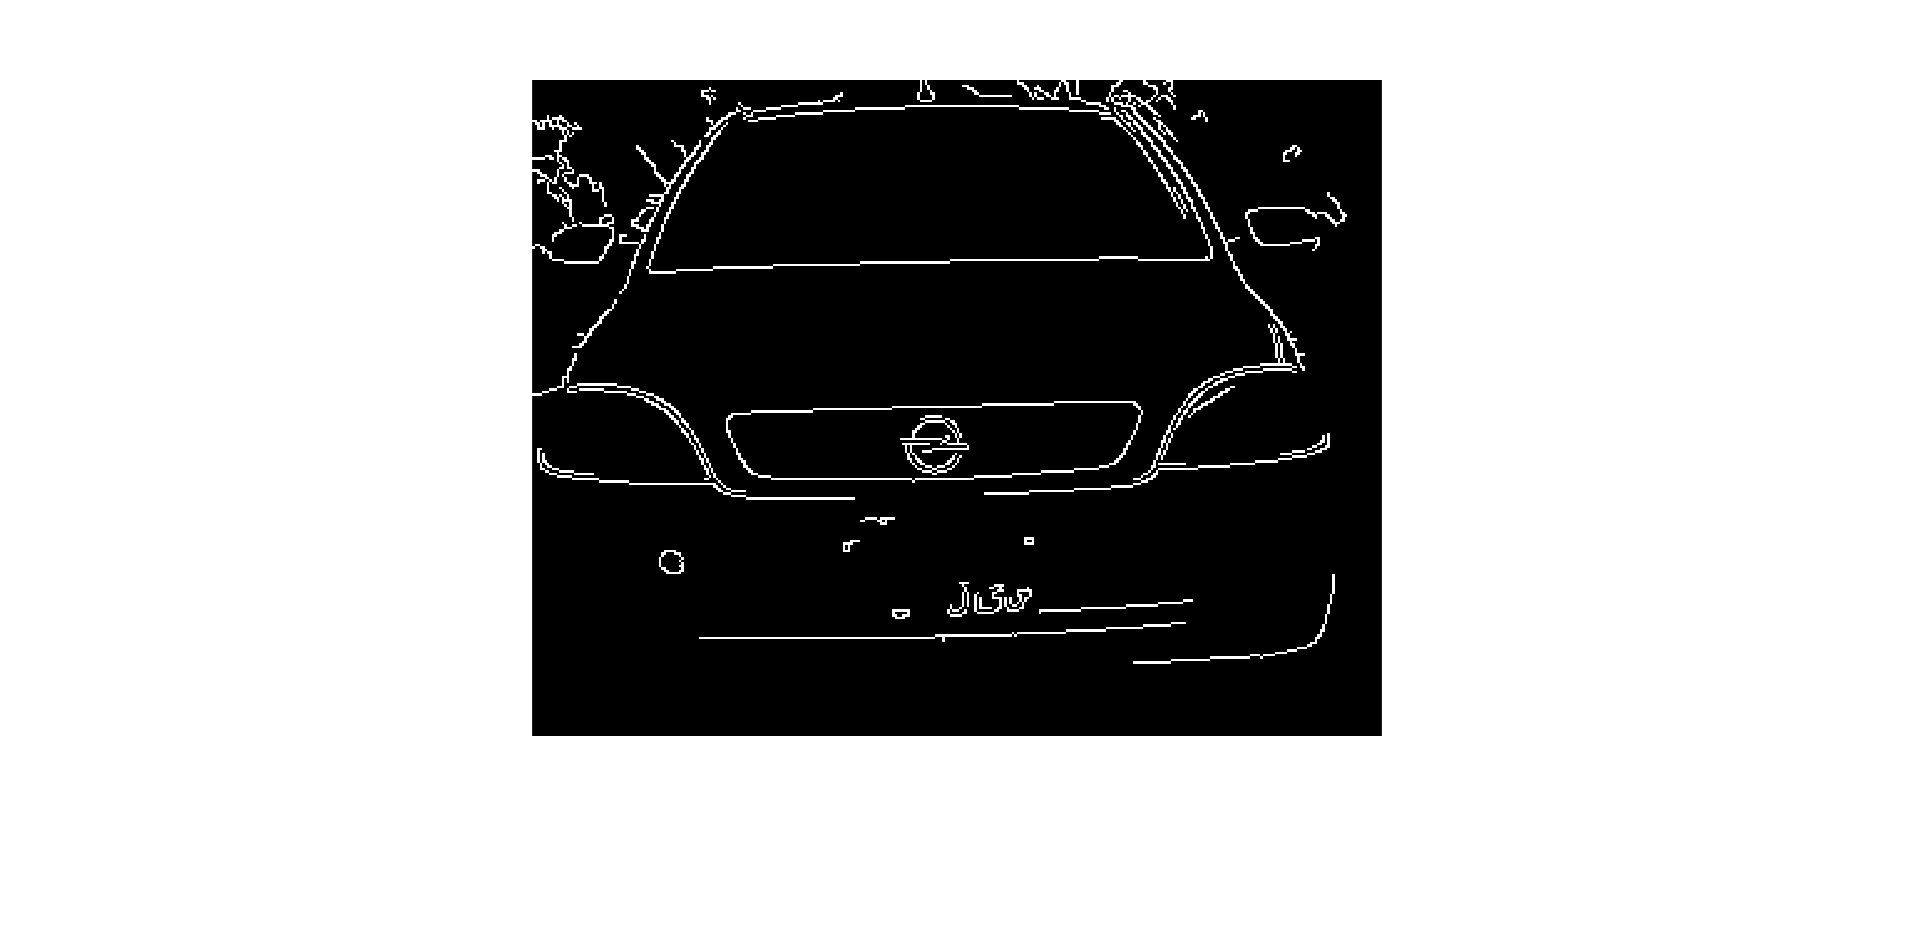

imgedge = edge(img2,"approxcanny",0.58);
imshow(imgedge);

then i noticed that the logo is exactly a circle and in the middle so i used imfindcircles which takes input radus range for a circle and return all circles in an image between those two values, and viscricles is only to display a circle on the image on the logo place.

[center,rad] = imfindcircles(img2,[10,100])

center =   162.1715  146.9549


rad = 11.3122

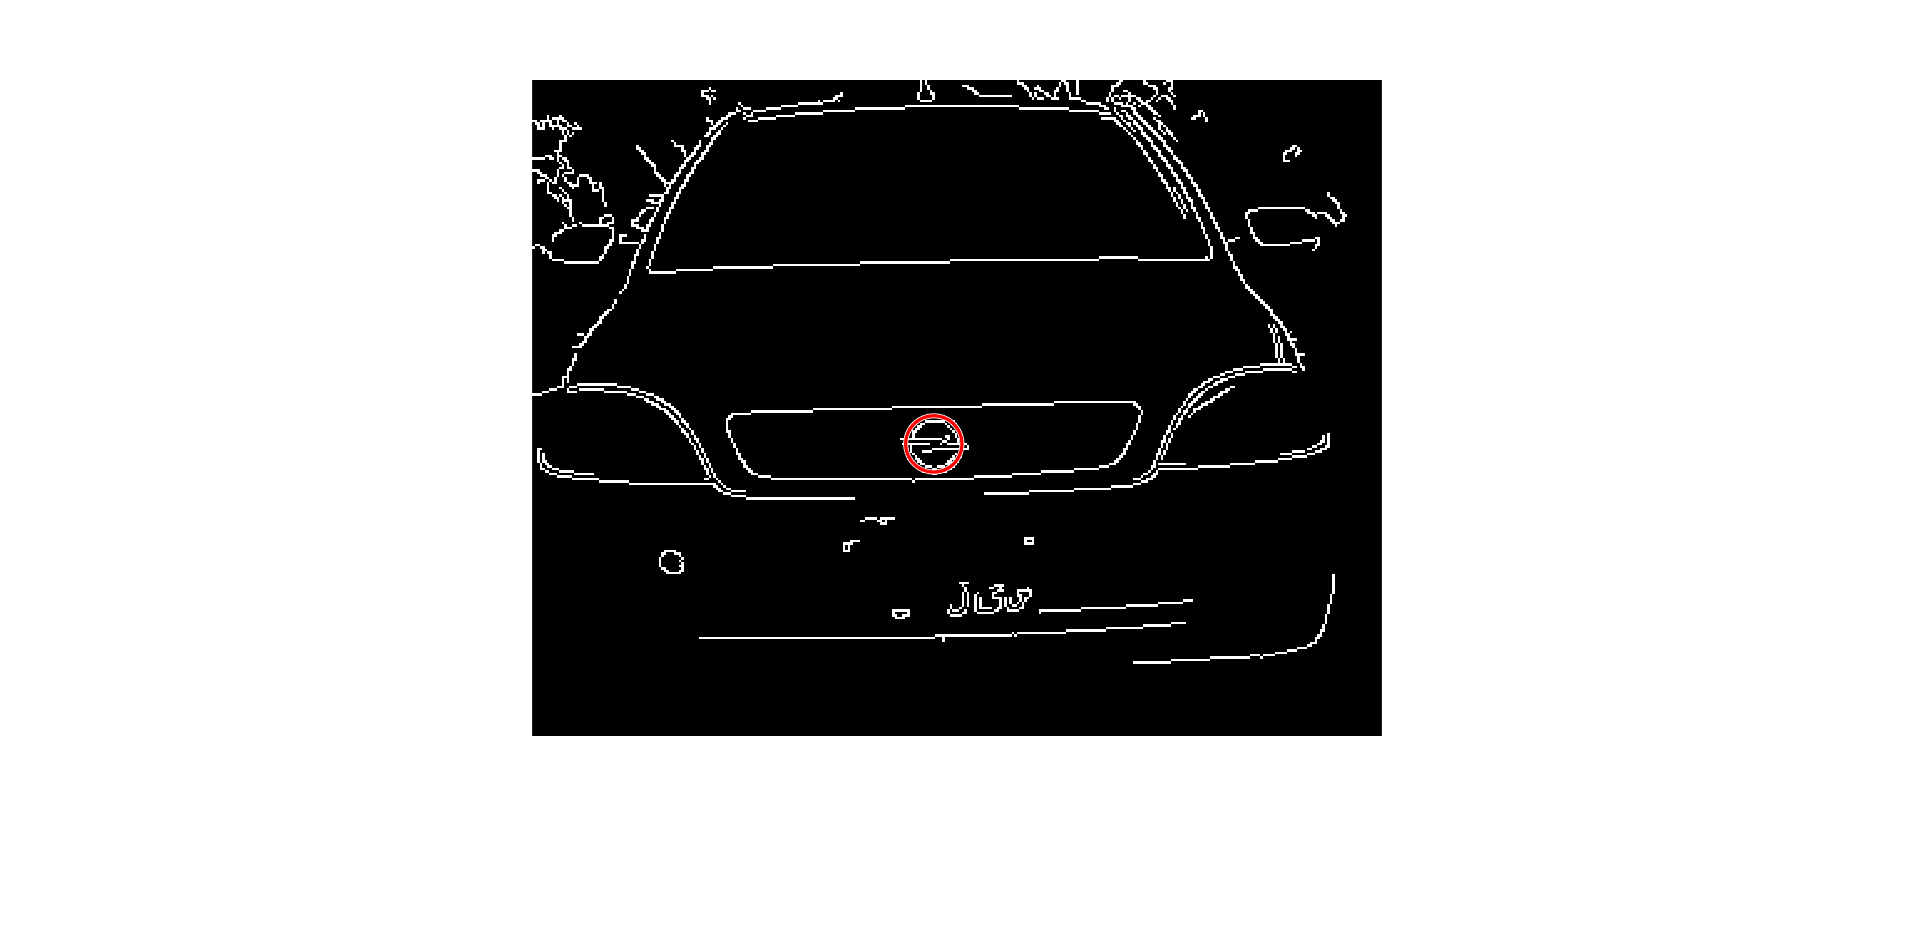

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties



viscircles(center,rad)

then i just crop the image around this circle to get the logo.

rad = rad * 1.2;
c1 = uint8(center(1) - rad);
c2 = uint8(center(1) + rad);
c3 = uint8(center(2) - rad);
c4 = uint8(center(2) + rad);
logo2 = imgg2(c3:c4,c1:c2)

logo2 = 29×28 uint8 matrix
    67    61    59    60    62    40    55    55    30    42    39    15    52    44    42    38    37    37    36    35    36    48    34    33    41    39    39    40
    53    50    49    52    54    67    36    56    64    58    74    70    64    64    68    66    65    66    69    71    71    67    75    73    62    58    65    67
    58    57    57    59    61    75    36    51    57    30    30    36    33    44    29    24    41    50    42    37    43    40    54    54    48    51    52    42
    46    46    44    45    44    39    43    45    39    33    21    37    83    68    93    82    34     8    23    38    35    40    37    28    34    46    37    23
    38    38    36    35    33    32    47    30    39   118   185   196   180   193   181   197   221   178    84    25    24    44    42    35    34    37    35    34
    41    43    43    42    40    39    23    72   171   174    91    43    28     3     4    11    59   156   216   161    63  

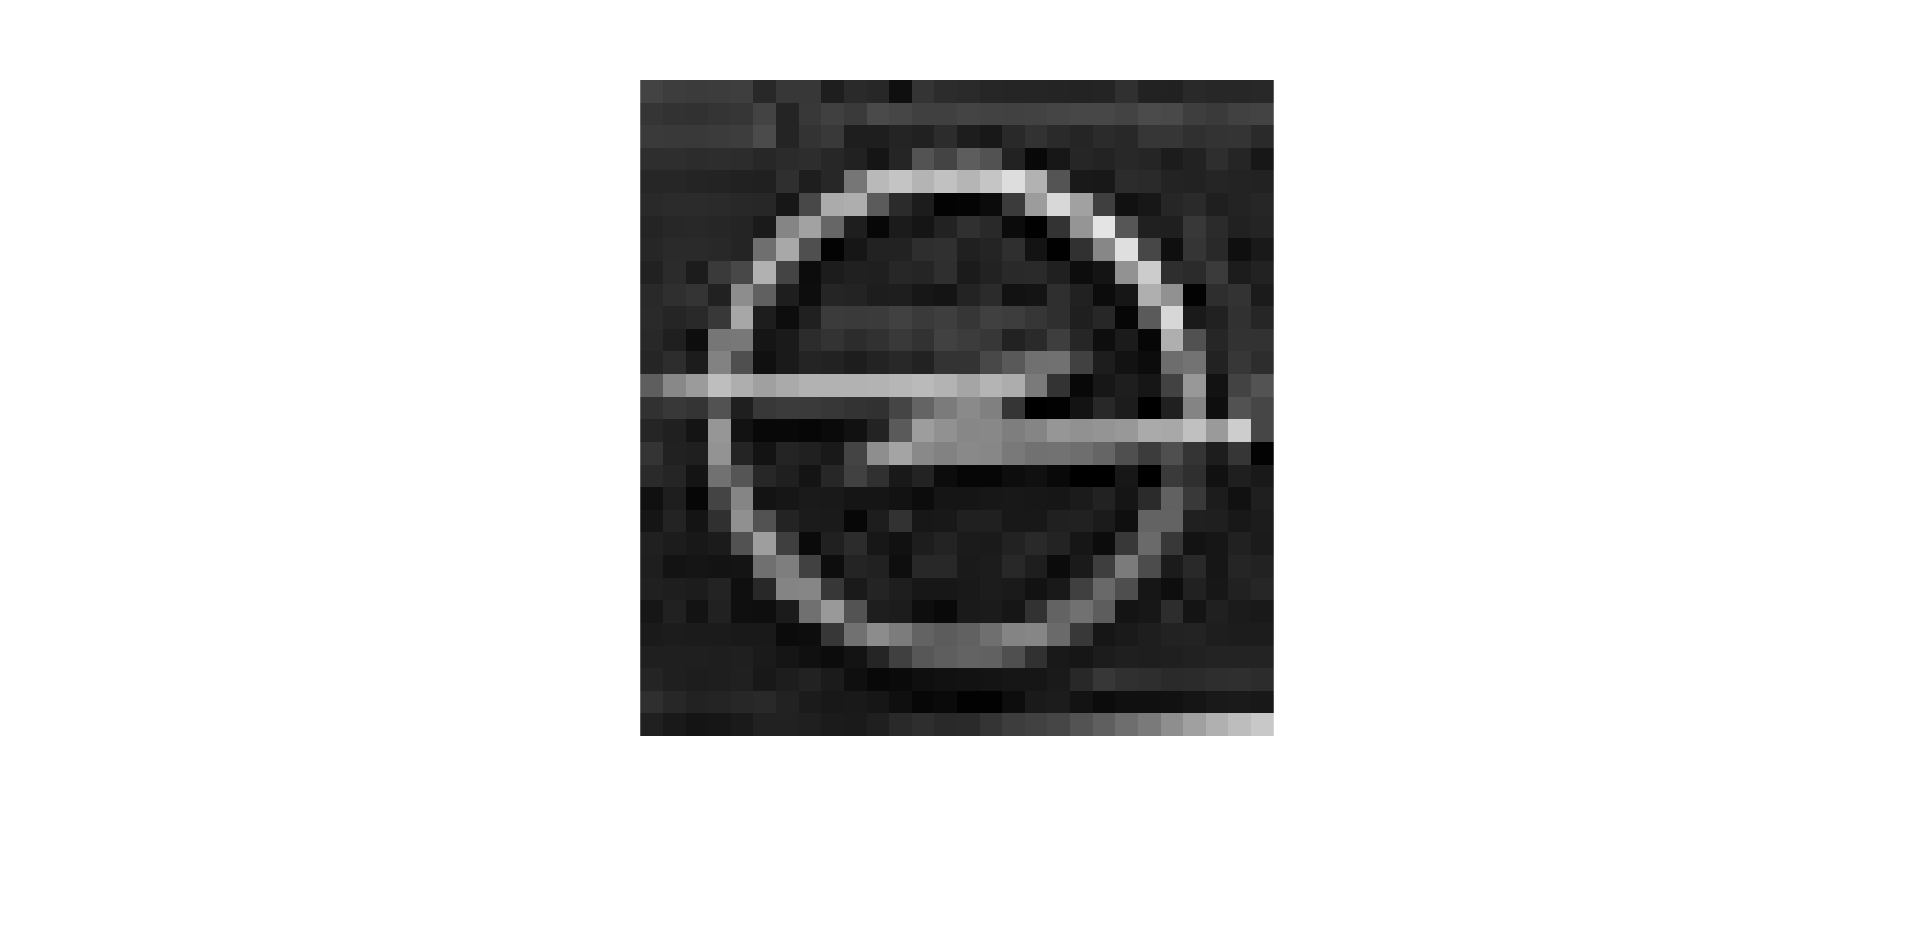

imshow(logo2)

logo2 = im2gray(logo2)

logo2 = 29×28 uint8 matrix
    67    61    59    60    62    40    55    55    30    42    39    15    52    44    42    38    37    37    36    35    36    48    34    33    41    39    39    40
    53    50    49    52    54    67    36    56    64    58    74    70    64    64    68    66    65    66    69    71    71    67    75    73    62    58    65    67
    58    57    57    59    61    75    36    51    57    30    30    36    33    44    29    24    41    50    42    37    43    40    54    54    48    51    52    42
    46    46    44    45    44    39    43    45    39    33    21    37    83    68    93    82    34     8    23    38    35    40    37    28    34    46    37    23
    38    38    36    35    33    32    47    30    39   118   185   196   180   193   181   197   221   178    84    25    24    44    42    35    34    37    35    34
    41    43    43    42    40    39    23    72   171   174    91    43    28     3     4    11    59   156   216   161    63  

then same as before we ably feature detection

image2=logo2;

fftI2=fft2(double(image2));
imagefeatures2=abs(fftI2(:));
imagefeatures2=sort(imagefeatures2,'descend');
imagefeatures2=imagefeatures2(1:3);

for i=1:4
nearesy2(i)=sqrt((imagefeatures2(1)-features(1,i))^2+(imagefeatures2(2)-features(2,i))^2+(imagefeatures2(3)-features(3,i))^2);
end

nearesy2

nearesy2 = 	1.0e+06 *

    1.8503    0.6661    1.5057    5.2770


[MinResult2,Index2]=min(nearesy2)

MinResult2 = 6.6610e+05

Index2 = 2

now our third image.

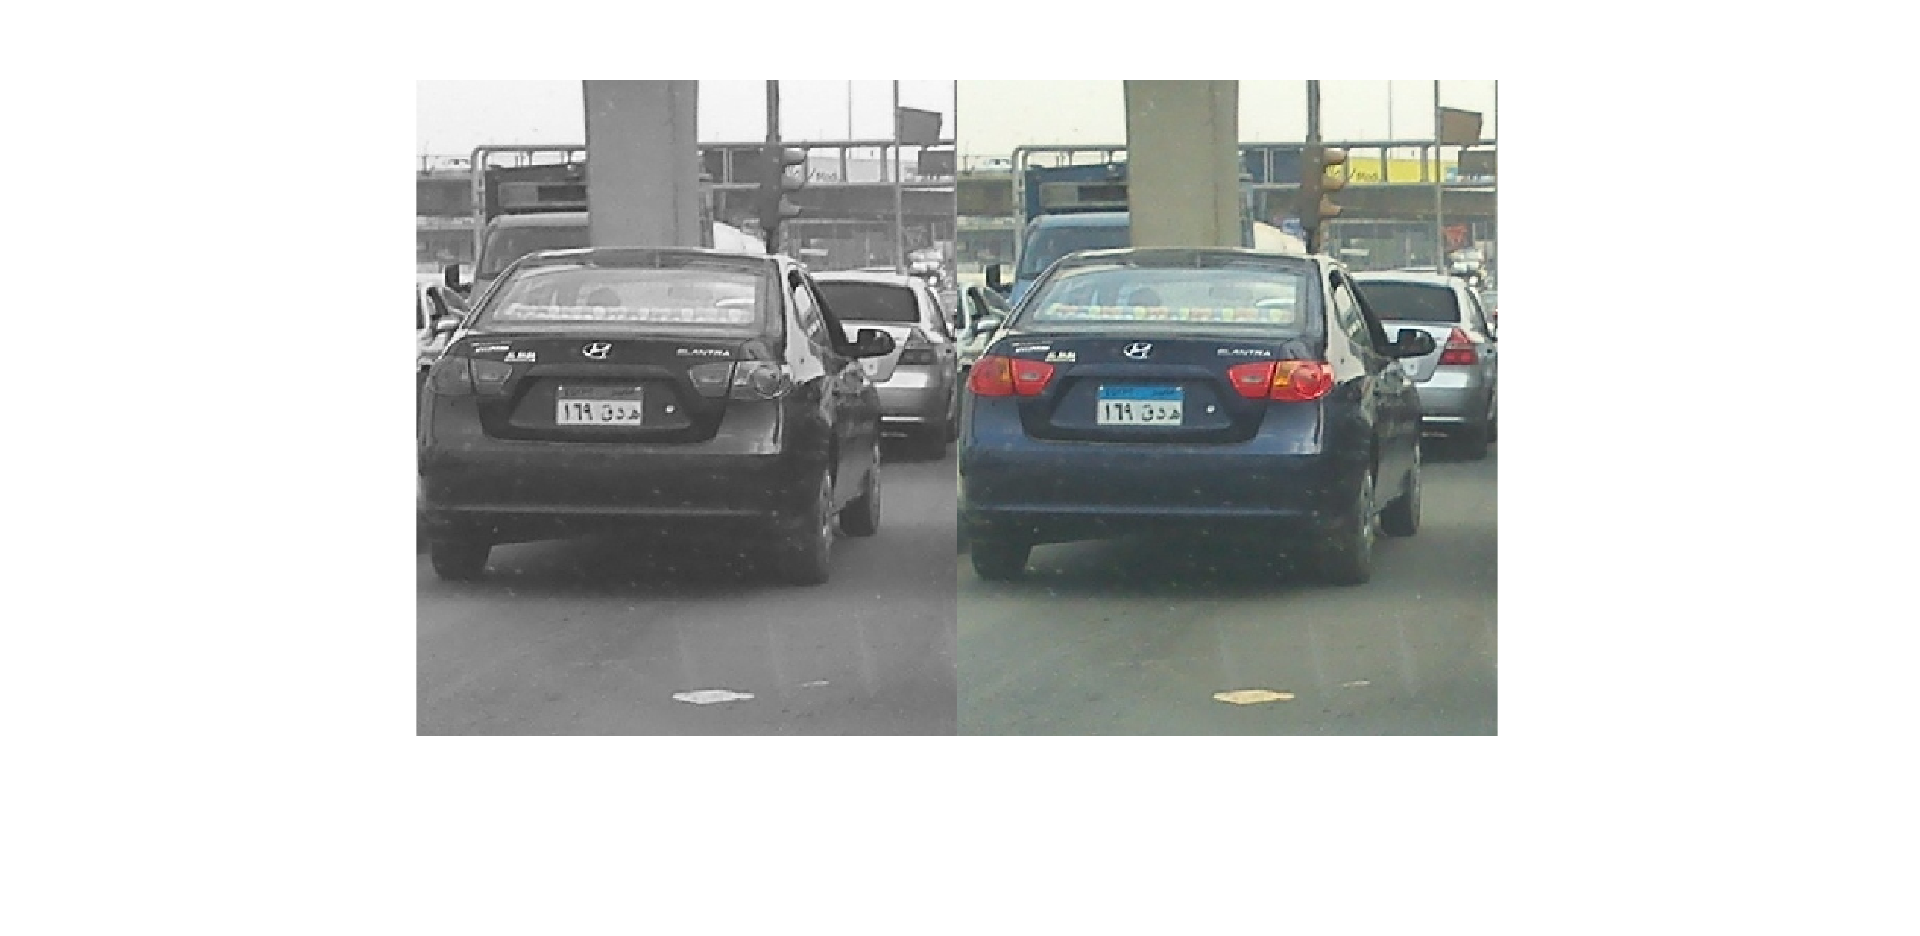

imgg3 = imread("courses\image project\Case2\Case2-Rear1.jpg");

img3 = im2gray(imgg3);

montage({img3,imgg3});

nearly the same thing with the first photo, first filter then some segmentation.

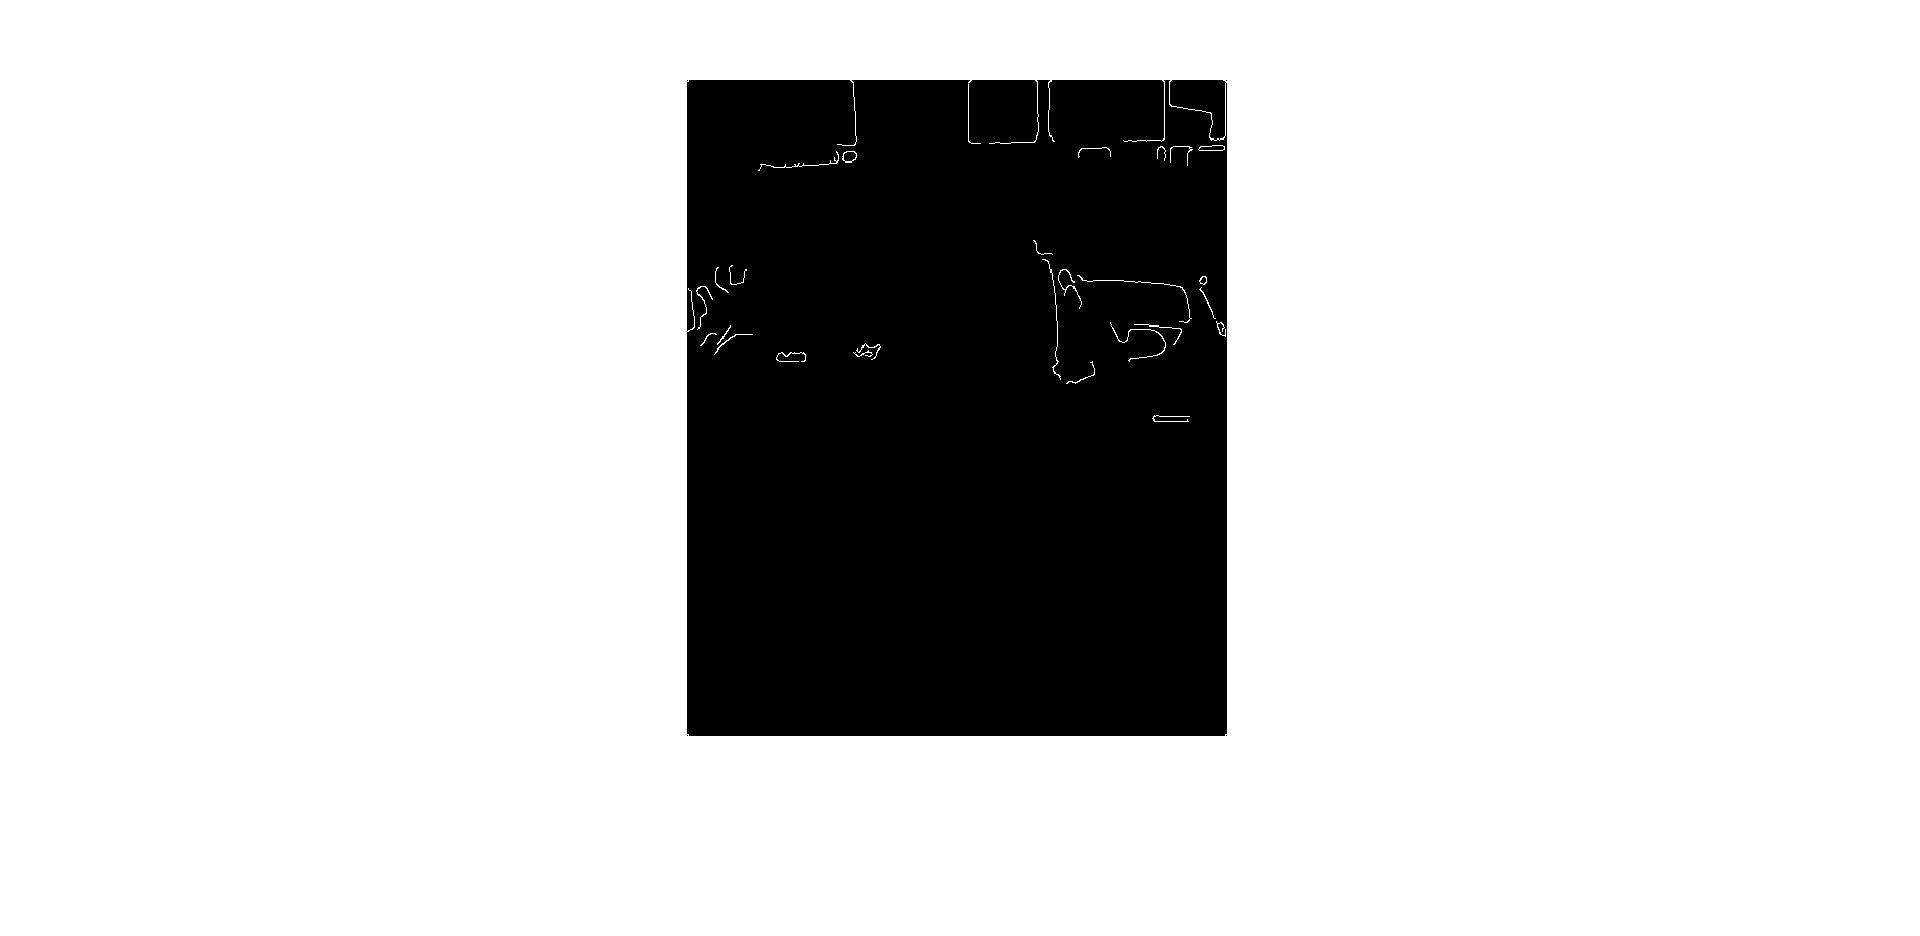

imgFilt3 = medfilt2(img3,[5 5]);
imge3 = edge(imgFilt3,"approxcanny",0.4);
imshow(imge3)

se3 = strel("disk", 3)

se3 = strel is a disk shaped structuring element with properties:

      Neighborhood: [5×5 logical]
    Dimensionality: 2


imge3 = imfill(imge3,"holes")

imge3 = 628×517 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

imge3 = imclose(imge3,se3)

imge3 = 628×517 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  


imge3 = imopen(imge3,se)

imge3 = 628×517 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

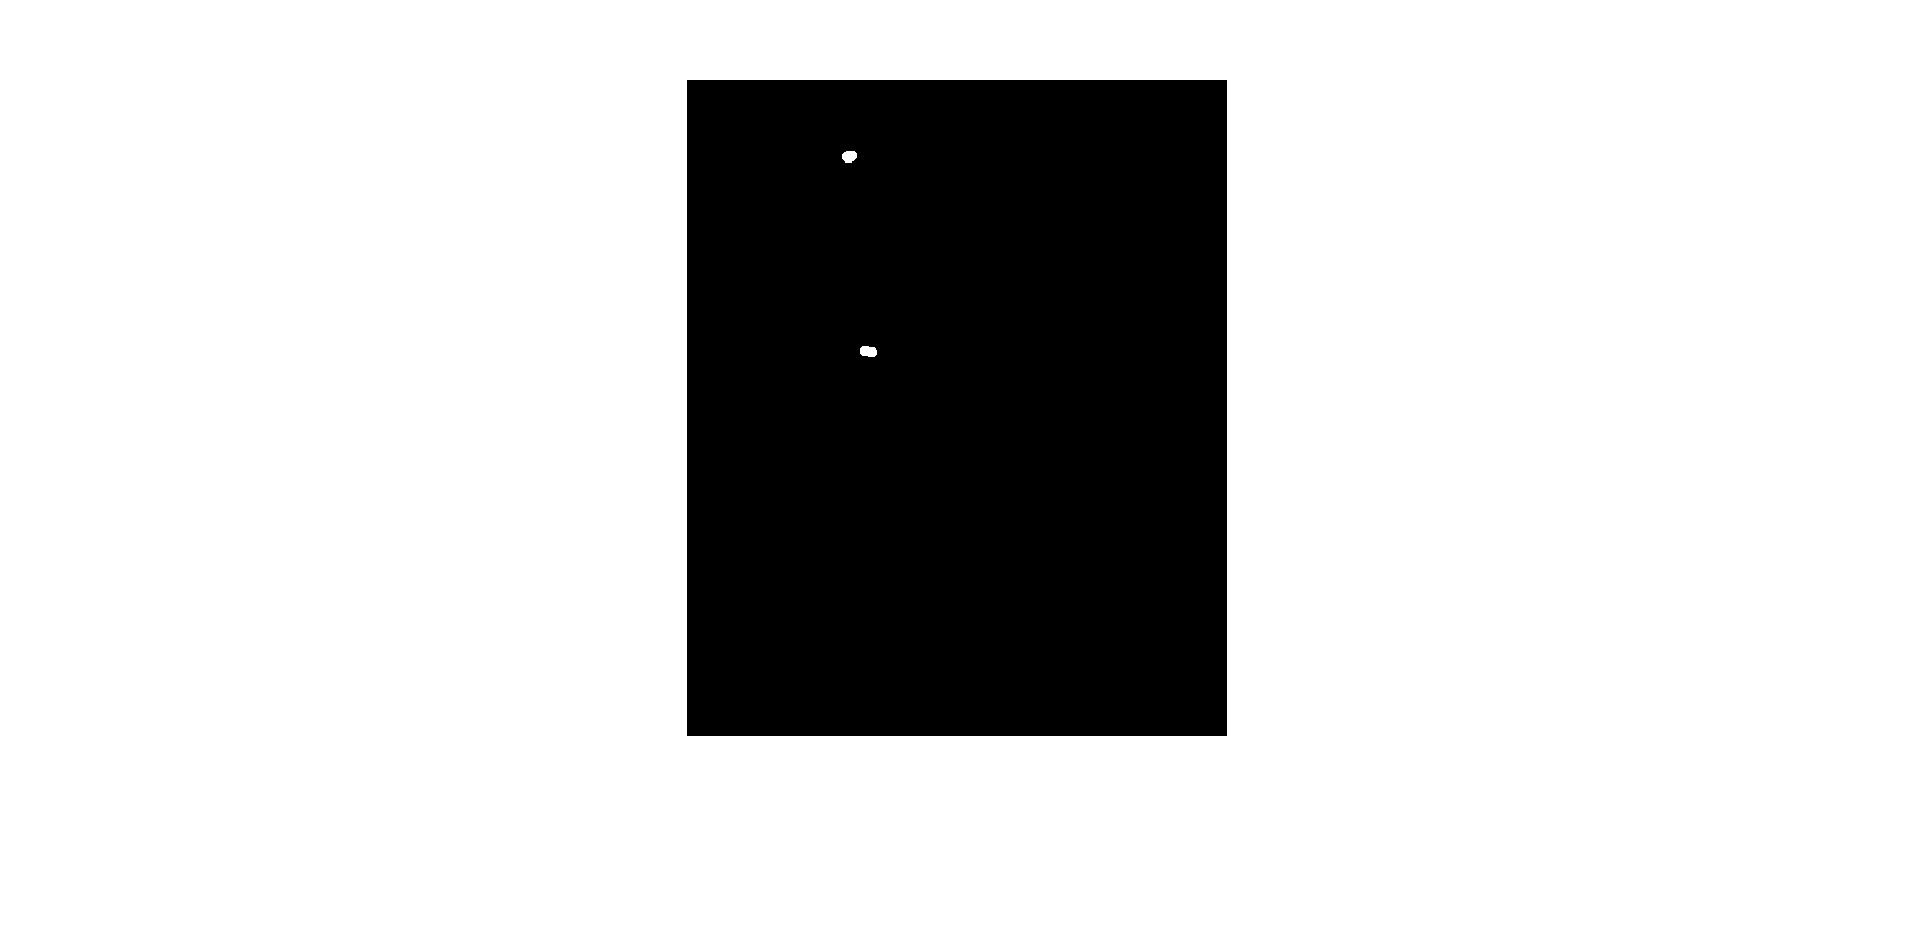

imshow(imge3)

then other function with diffrent segmentation method. the function is explianed in the function file.

gg3 = segmentImagev3(imgFilt3)

gg3 = 628×517 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

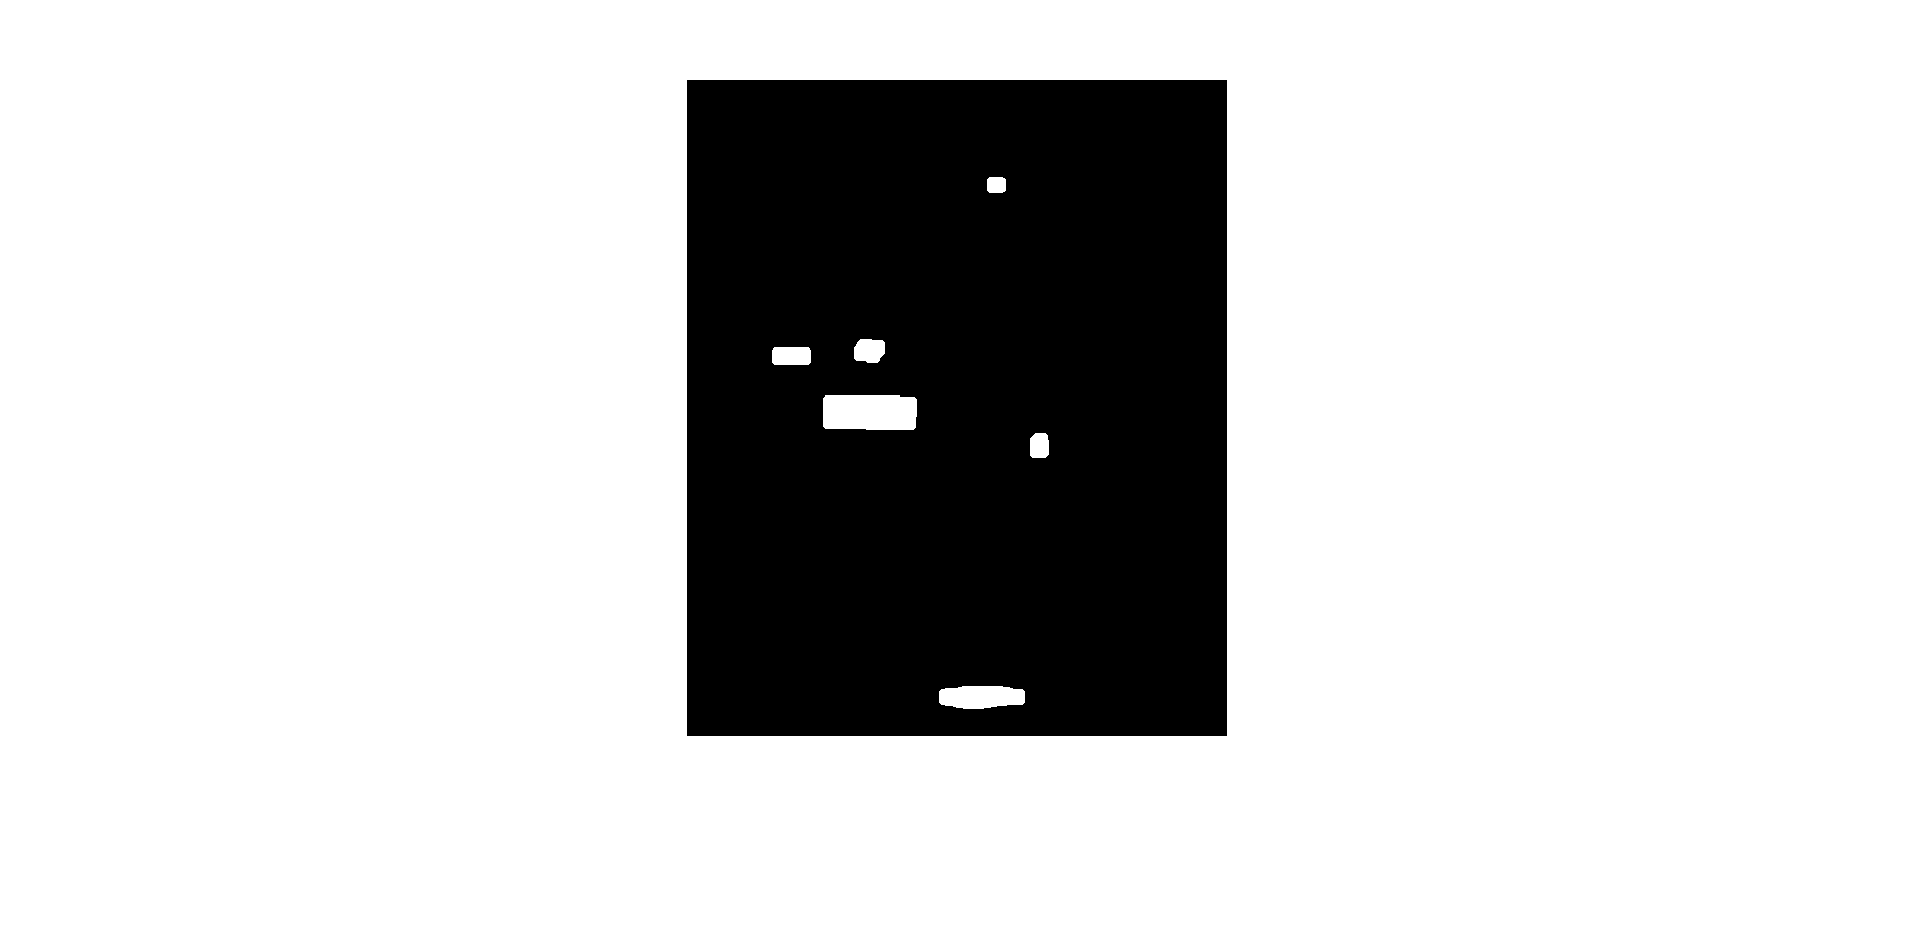

imshow(gg3)

then we combine them to get the logo.

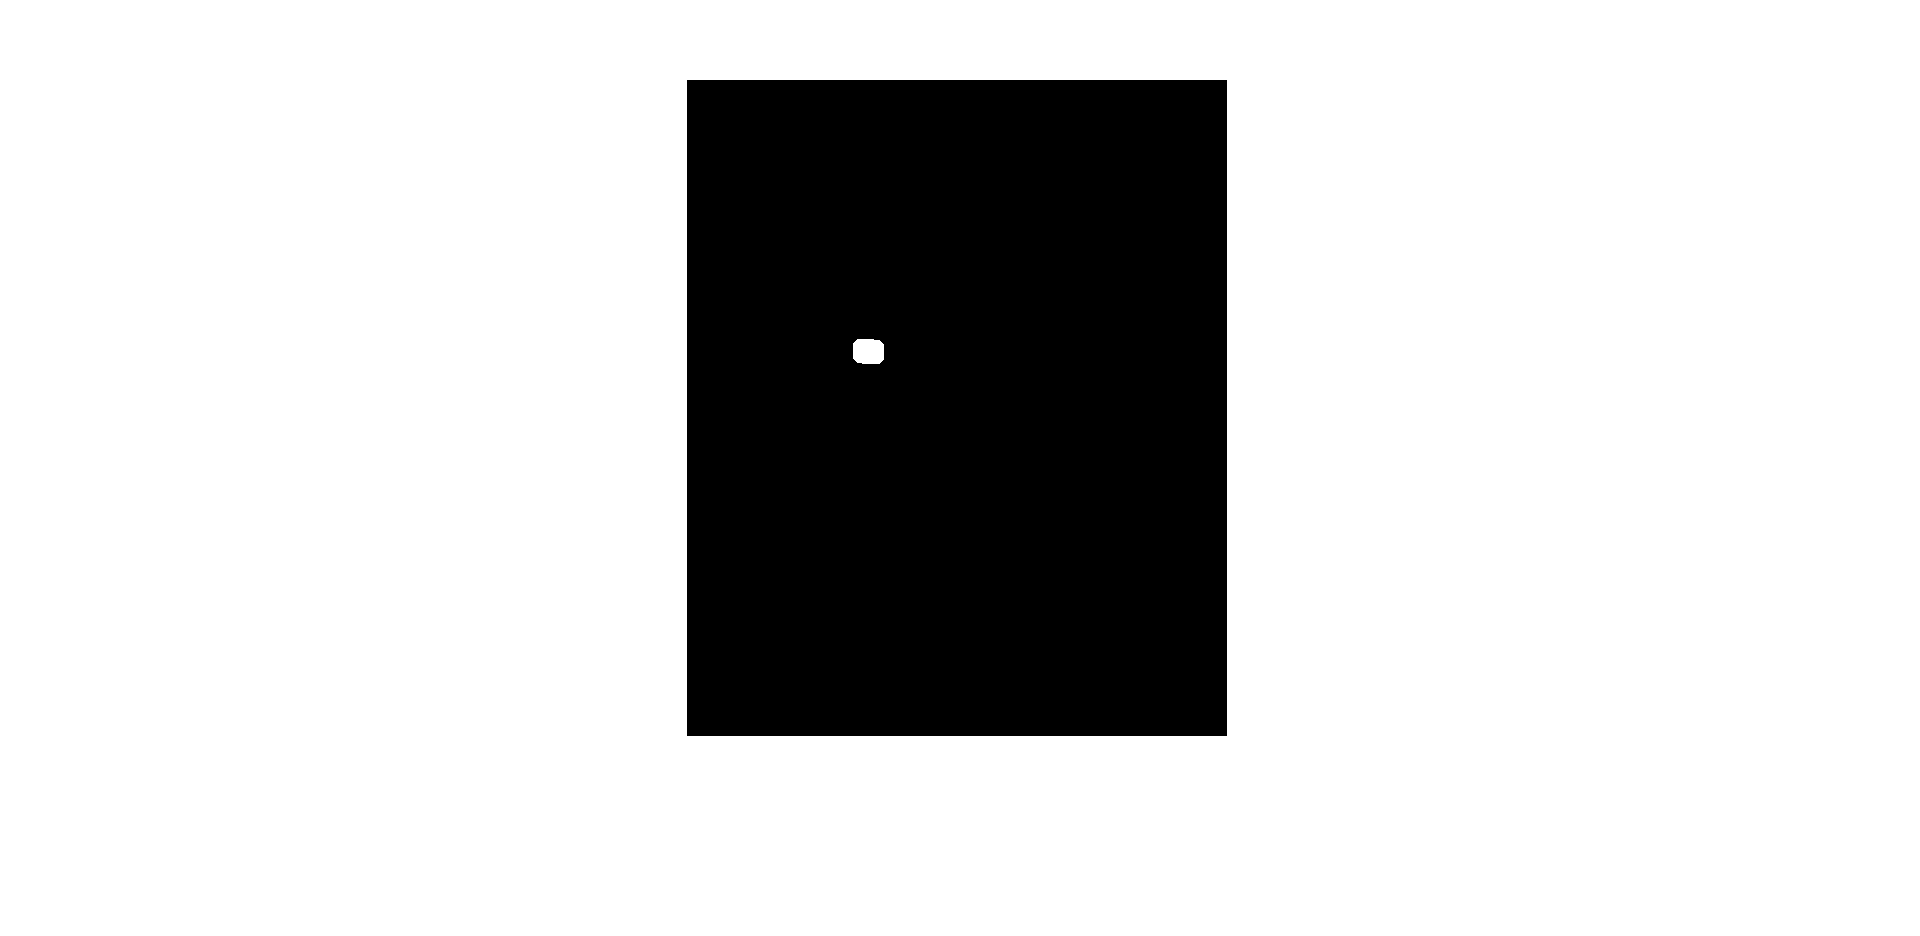

ff3 = gg3 & imge3;
se33 = strel('disk', 8, 8);
ff3 = imdilate(ff3, se33);
imshow(ff3)

same function and same crop.

logoinfo3=regionprops(ff3)

logoinfo3 = struct with fields:
           Area: 661
       Centroid: [174.4917 260.5174]
    BoundingBox: [159.5000 248.5000 30 24]


logo3 = imcrop(imgg3,logoinfo3.BoundingBox)

logo3 = 25×31×3 uint8 array
logo3(:,:,1) =

    67    64    68    68    61    62    58    63    69    68    56    69    67    58    60    62    70    67    61    69    68    68    72    66    64    66    71    72    67    73    67
    62    53    57    53    53    52    59    56    48    39    22    40    32    18    23    42    52    57    45    49    53    48    44    41    38    55    55    53    51    58    59
    60    57    63    50    60    51    46    56    40    27    22    24    24    37    39    45    60    59    52    57    60    52    44    41    38    39    39    47    53    53    55
    63    61    63    55    41    42    37    42    49    47    55    71   102   120   109    92    89    90    98   103    89    75    68    56    49    33    29    37    52    50    56
    71    61    45    56    35    58    85    67    86    69   106   185   222   174   125   118    98   105   124   139   124   116   109    86    86    98    74    48    49    43    58
    60    56    47   

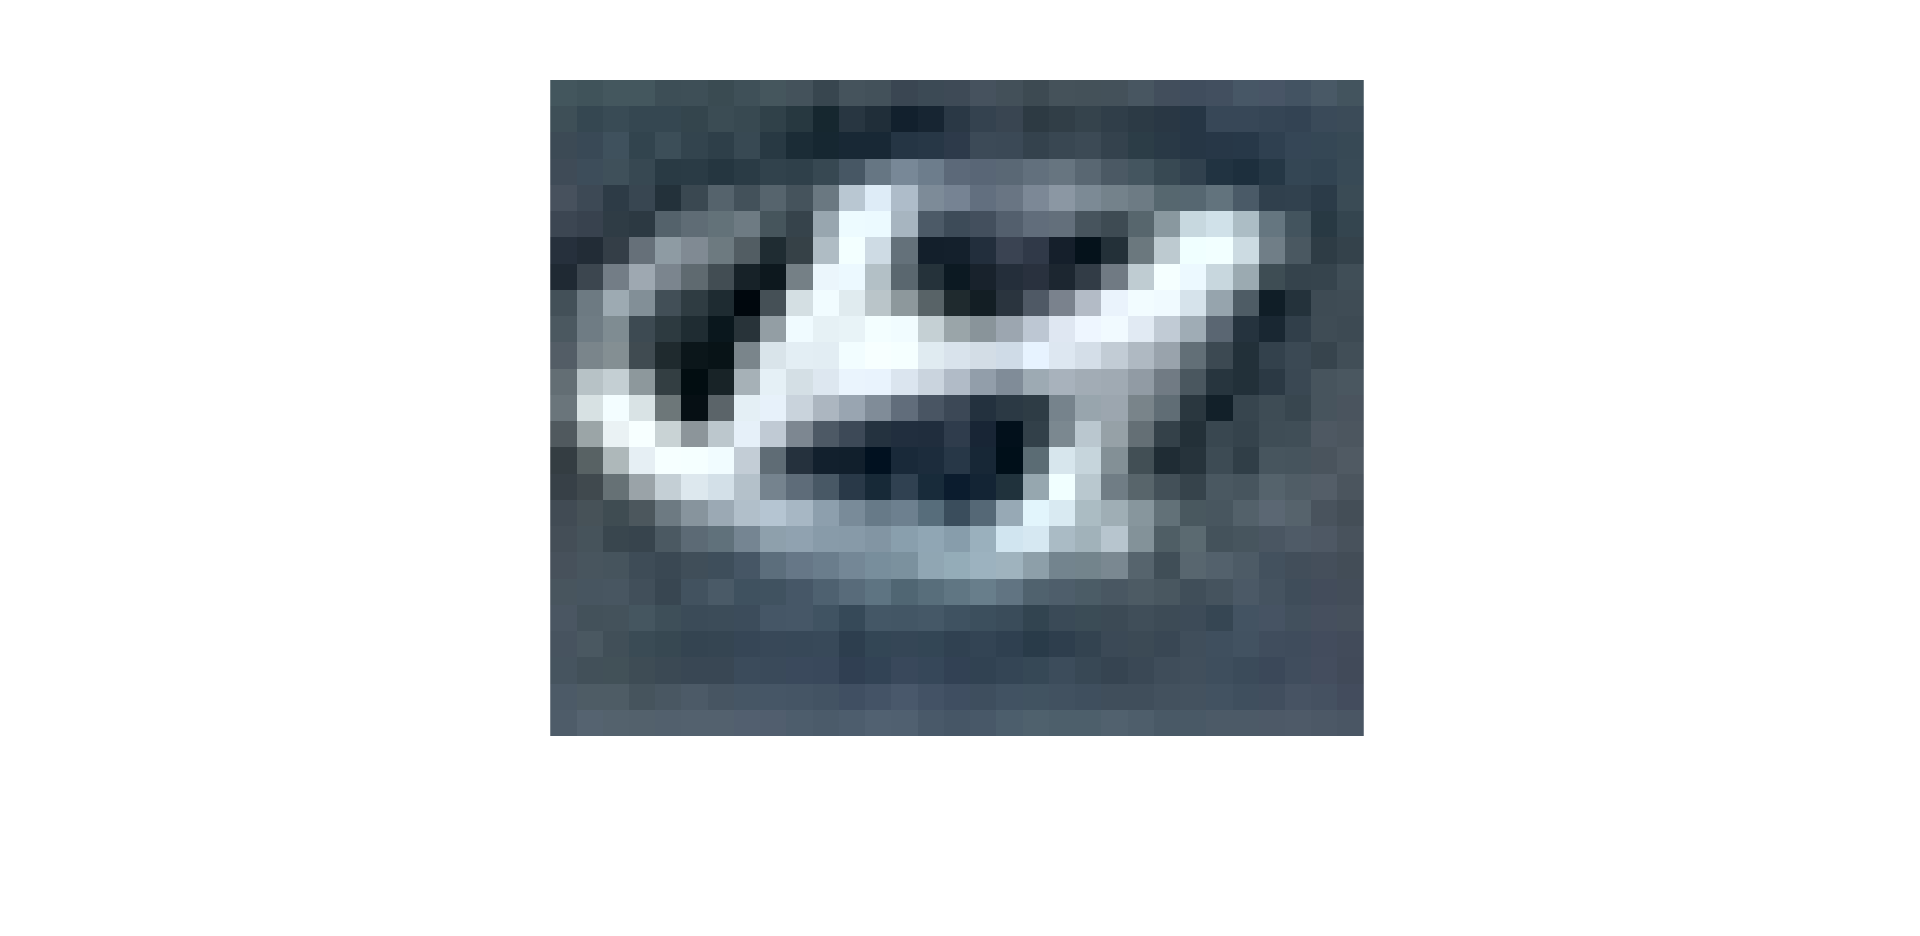


imshow(logo3)

logo3 = im2gray(logo3)

logo3 = 25×31 uint8 matrix
    81    78    82    82    74    75    71    76    82    79    67    80    78    68    71    72    80    77    71    79    78    78    83    76    75    77    84    83    80    86    80
    75    67    71    67    67    65    72    69    61    52    35    51    43    29    34    53    63    67    55    59    64    59    55    52    51    68    68    66    64    71    72
    71    70    77    64    74    64    59    69    53    40    35    37    37    50    52    56    71    70    63    68    71    63    57    54    51    52    53    61    67    67    69
    73    74    76    68    54    55    50    55    62    60    68    84   115   133   122   103   100   101   109   114   100    86    81    69    62    47    43    51    66    64    70
    79    71    56    67    46    69    96    78    97    80   117   196   233   185   136   129   109   115   134   149   135   127   120    99    99   111    87    61    62    56    71
    68    64    57    54    95   105  

logo3 = filter2(fspecial('average',3),logo3)/255;


and finnaly feature detection.

image3=logo3;

fftI3=fft2(double(image3));
imagefeatures3=abs(fftI3(:));
imagefeatures3=sort(imagefeatures3,'descend');
imagefeatures3=imagefeatures3(1:3);

for i=1:4
nearesy3(i)=sqrt((imagefeatures3(1)-features(1,i))^2+(imagefeatures3(2)-features(2,i))^2+(imagefeatures3(3)-features(3,i))^2);
end

nearesy3

nearesy3 = 	1.0e+06 *

    1.8950    0.7108    1.5504    5.3205


[MinResult3,Index3]=min(nearesy3)

MinResult3 = 7.1080e+05

Index3 = 2

fourth image.

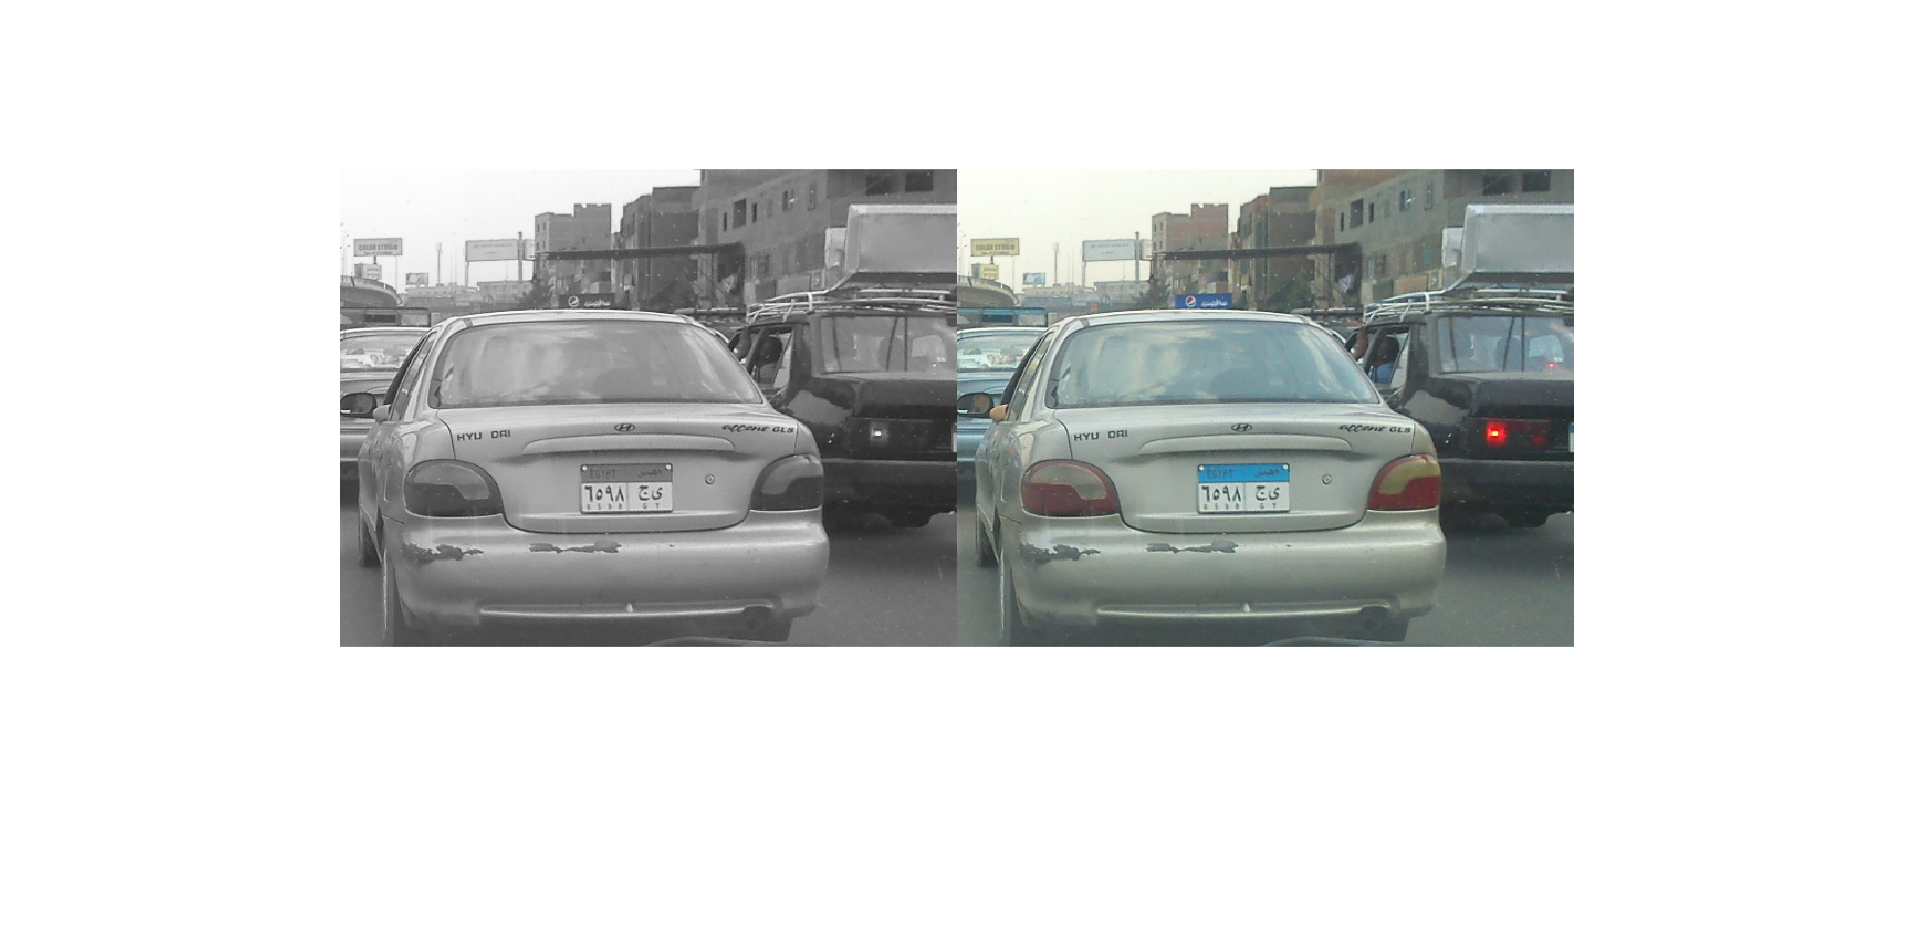

imgg4 = imread("courses\image project\Case2\Case2-Rear2.jpg");

img4 = im2gray(imgg4);

montage({img4,imgg4});

nearly the same like first and third one but this one was a little hard.

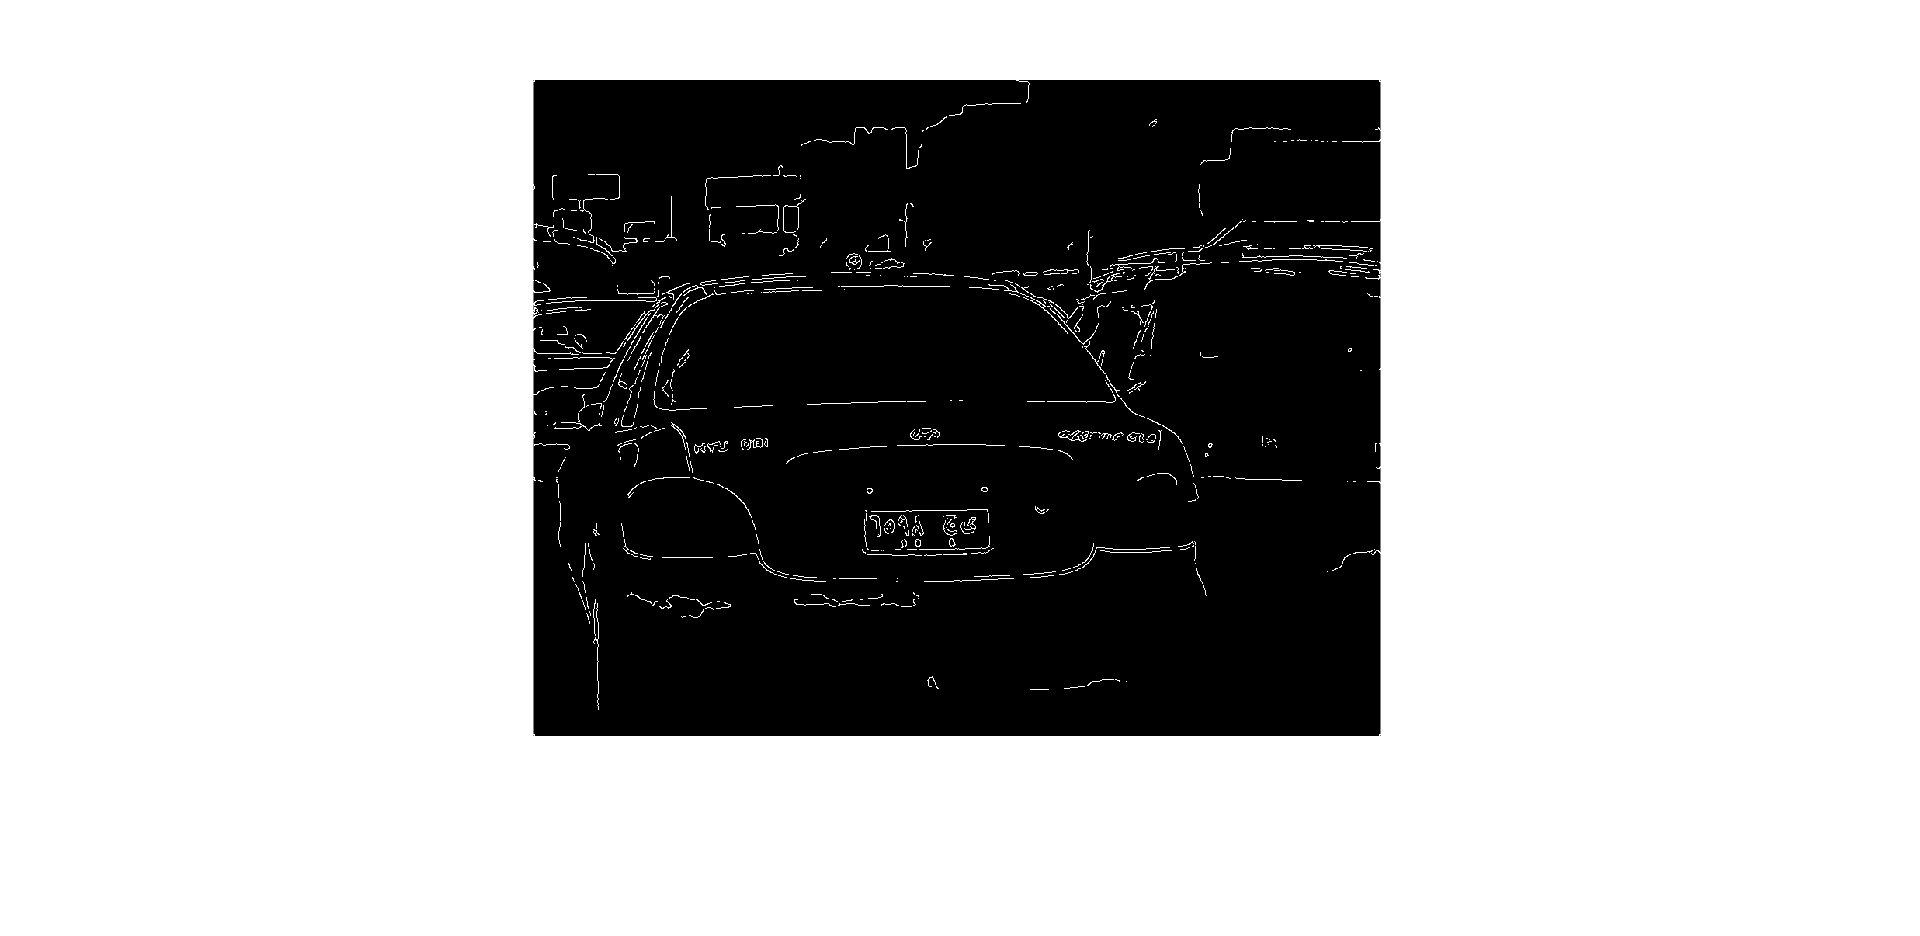

imgFilt4 = medfilt2(img4,[5 5]);
imge4 = edge(imgFilt4,"approxcanny", 0.15);
imshow(imge4)

se4 = strel("disk", 7)

se4 = strel is a disk shaped structuring element with properties:

      Neighborhood: [13×13 logical]
    Dimensionality: 2


imge4 = imfill(imge4,"holes")

imge4 = 845×1091 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

imge4 = imclose(imge4,se4)

imge4 = 845×1091 logical array
   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 


se4 = strel("disk", 9)

se4 = strel is a disk shaped structuring element with properties:

      Neighborhood: [17×17 logical]
    Dimensionality: 2



imge4 = imopen(imge4,se4)

imge4 = 845×1091 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

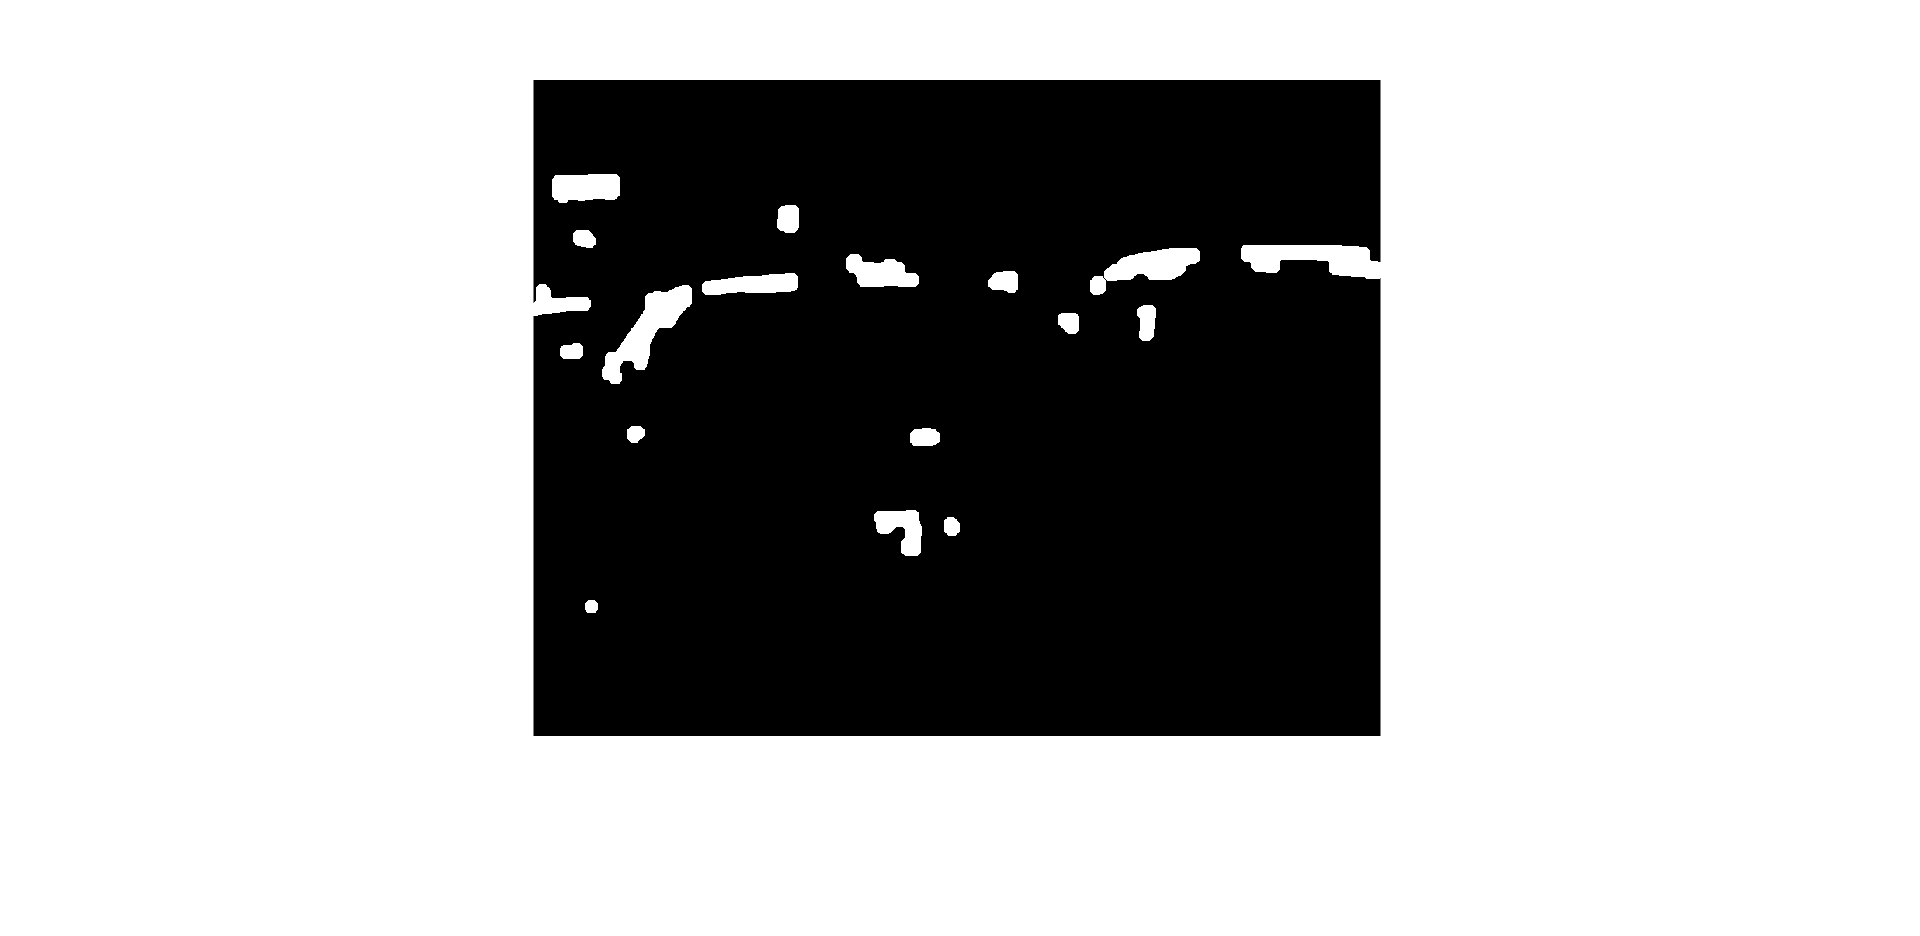

se = strel('rectangle', [4 16]);
img4 = imerode(img4, se);
imshow(imge4)

this time the function and the segmentation wasnt complete. the expliantion is on segmetImagesv4.m file

gg4 = segmentImagev4(imgFilt4)

gg4 = 845×1091 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

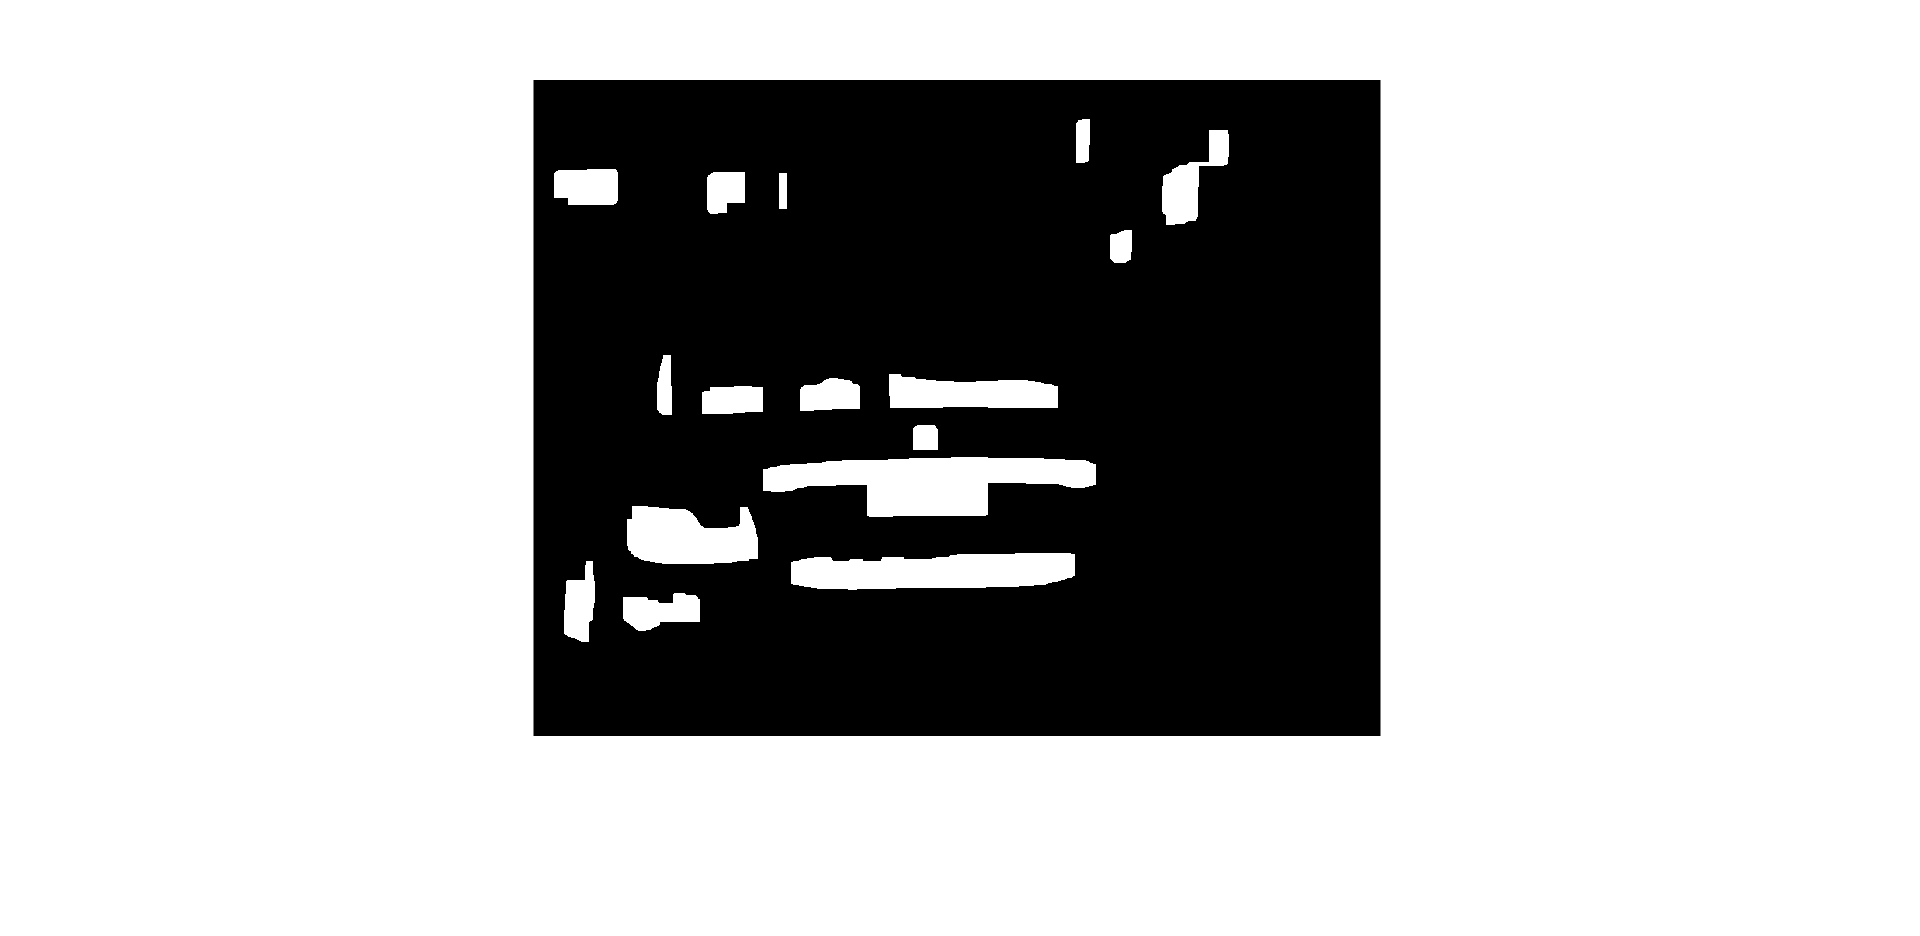

imshow(gg4)

as you can see here there are 6 object.

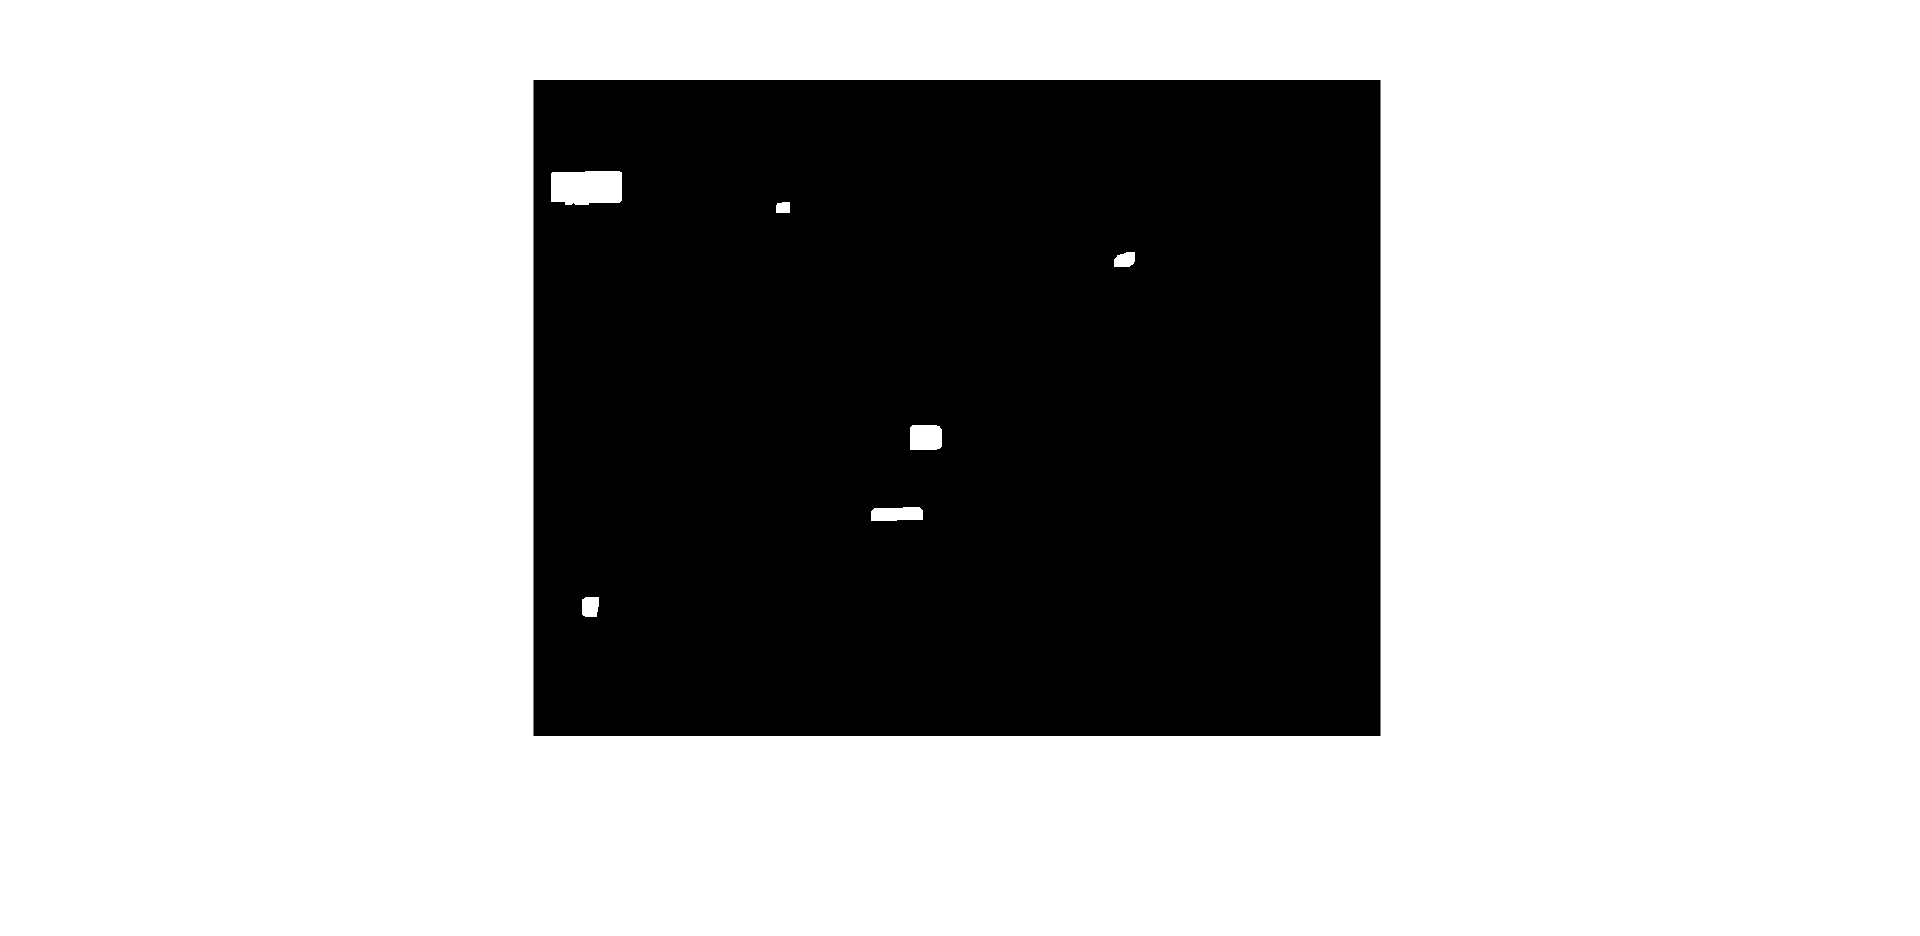

ff4 = gg4 & imge4;
se44 = strel('rectangle', [10 10]);
ff4 = imdilate(ff4, se44);
imshow(ff4)

so i needed to specify which object i need.

logoinfo4=regionprops(ff4)

logoinfo4 = 6×1 struct array with fields:
    Area
    Centroid
    BoundingBox


logo4 = imcrop(imgg4,logoinfo4(5).BoundingBox)

logo4 = 33×42×3 uint8 array
logo4(:,:,1) =

   208   208   210   213   215   215   214   214   215   214   211   215   216   216   214   212   211   209   206   214   211   210   213   215   216   215   215   215   215   215   213   213   213   213   212   211   211   213   213   210   208   210
   206   204   206   211   211   211   209   209   209   207   204   199   202   204   204   208   212   212   208   207   205   206   207   205   203   207   213   214   207   204   207   209   205   201   201   201   202   205   208   205   200   199
   200   199   200   201   201   201   201   201   201   199   197   200   201   201   199   198   198   196   194   202   201   199   197   193   192   197   202   200   193   190   194   197   193   188   187   191   191   193   196   195   192   192
   189   187   188   185   185   186   188   190   190   190   189   187   188   190   190   187   184   185   186   192   190   190   188   187   187   186   185   185   181   179   177   179   18

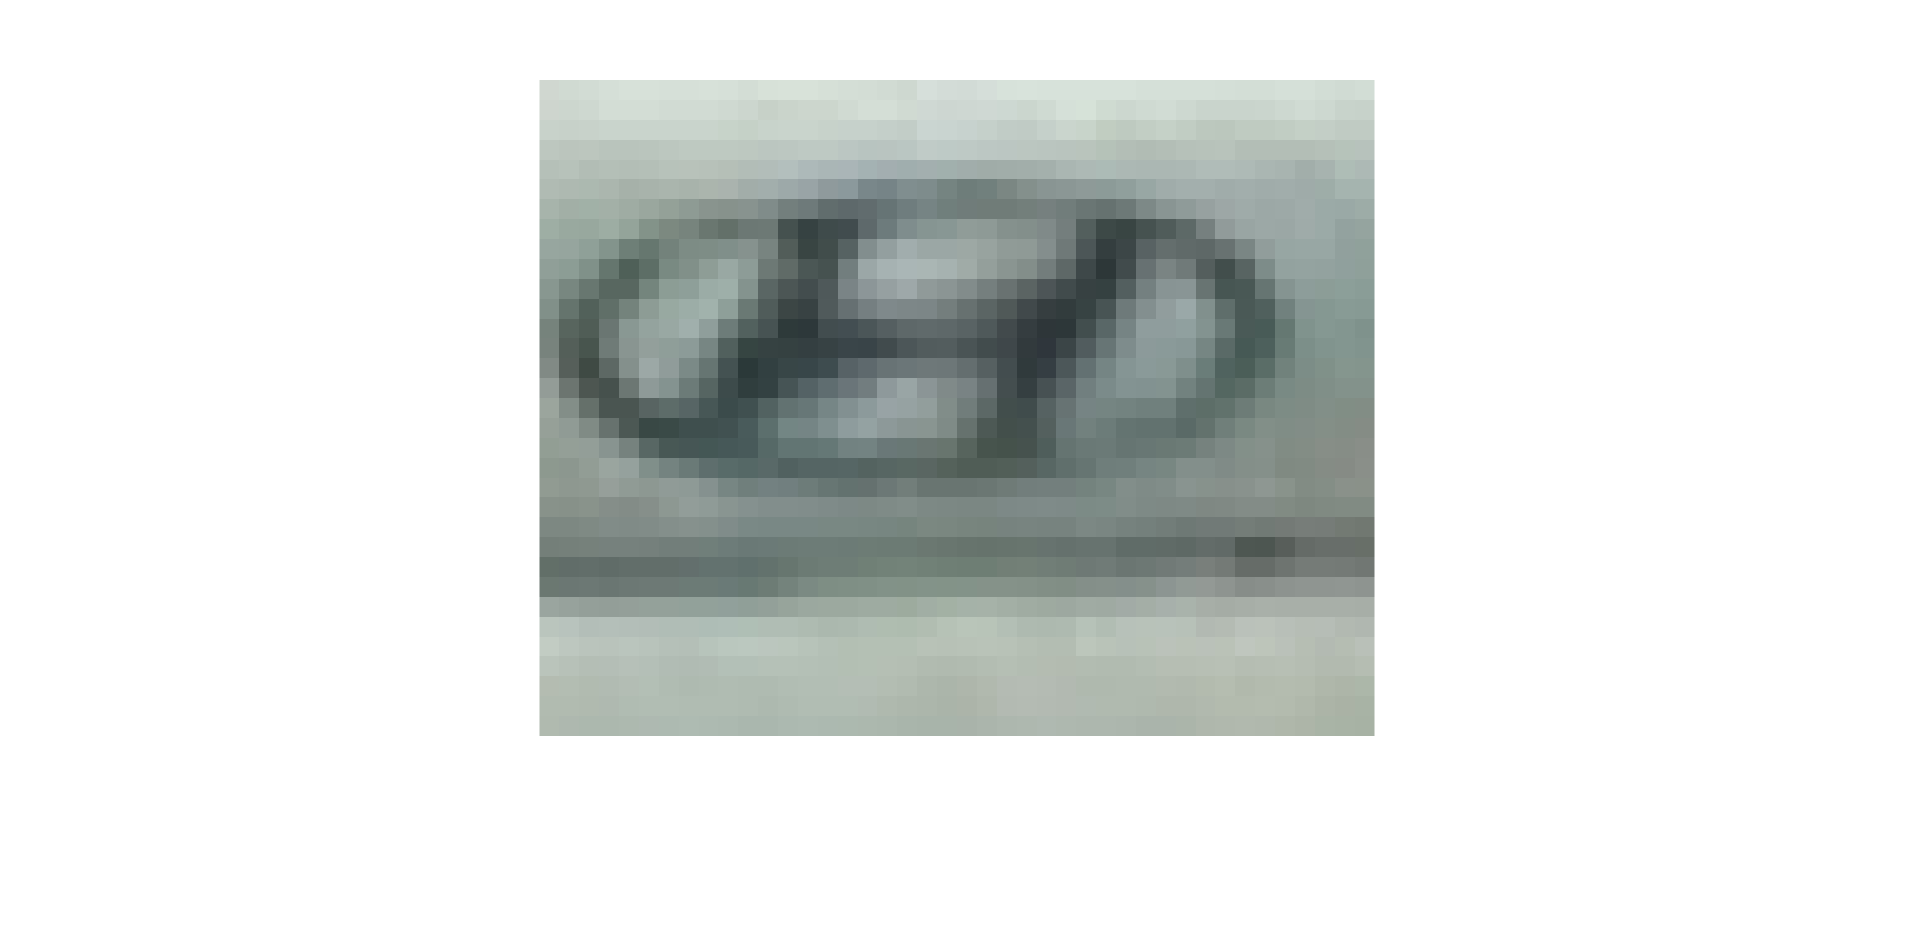

imshow(logo4)


logo4 = im2gray(logo4)

logo4 = 33×42 uint8 matrix
   212   214   216   219   221   221   220   220   221   220   217   221   222   222   220   218   217   215   212   220   217   216   219   222   223   222   222   222   222   222   220   220   220   220   219   218   218   220   220   217   215   217
   210   210   212   217   217   217   215   215   215   213   210   205   208   210   210   214   218   218   214   213   211   212   213   212   210   214   220   221   214   211   214   216   212   208   208   208   209   212   215   212   207   206
   206   205   206   208   208   208   208   208   208   206   204   207   208   208   206   205   205   203   201   209   208   206   204   200   199   204   209   207   200   197   201   204   200   195   194   198   198   200   203   202   199   199
   195   193   194   192   192   193   195   197   197   197   196   194   195   197   197   194   192   192   194   199   198   197   195   194   194   193   192   192   189   186   184   186   189   190   191   1

logo4 = filter2(fspecial('average',3),logo4)/255;

then same with imagefeatures.

image4=logo4;

fftI4=fft2(double(image4));
imagefeatures4=abs(fftI4(:));
imagefeatures4=sort(imagefeatures4,'descend');
imagefeatures4=imagefeatures4(1:3);

for i=1:4
nearesy4(i)=sqrt((imagefeatures4(1)-features(1,i))^2+(imagefeatures4(2)-features(2,i))^2+(imagefeatures4(3)-features(3,i))^2);
end

nearesy4

nearesy4 = 	1.0e+06 *

    1.8945    0.7103    1.5499    5.3200


[MinResult4,Index4]=min(nearesy4)

MinResult4 = 7.1033e+05

Index4 = 2